**This code analysis the singularities by **

- defining the sufficient condition for each singularity

- studying the shape in the 4D joint sapce

First it's ncessary to find the Jacobian and the determinant of the Gofa robot arm

clear all;
close all;

% change the path of the directory
dir_path = '/Users/axel/Desktop/Axel/ETS/CoRo/Matlab/manipulator singularities/';
urdf_path = fullfile(dir_path, 'robot/crb15000_5_95/urdf/crb15000_5_95.urdf');

gofa = loadModel(urdf_path);


syms tet1 tet2 tet3 tet4 tet5 tet6

% Function to create Denavit–Hartenberg (DH) homogeneous transformation
DH = @(theta, d, a, alpha) [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
                            sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
                            0,           sin(alpha),             cos(alpha),            d;
                            0,           0,                      0,                     1];

% Denavit–Hartenberg table (classic convention) in [m]
T01 = simplify(DH(tet1,               0.265,  0,     -sym(pi/2)));
T12 = simplify(DH(tet2 - sym(pi/2),   0,      0.444,  0));
T23 = simplify(DH(tet3,               0,      0.110, -sym(pi/2)));
T34 = simplify(DH(tet4,               0.470,  0,      sym(pi/2)));
T45 = simplify(DH(tet5,               0,      0.080, -sym(pi/2)));
T56 = simplify(DH(tet6,               0.101,  0,      0));

% All the homogeneous transformation matrices in the 0 frame
T00 = eye(4); % manually put the axis of joint 1

T02 = simplify(T01 * T12);
T03 = simplify(T02 * T23);
T04 = simplify(T03 * T34);
T05 = simplify(T04 * T45);
T06 = simplify(T05 * T56);

% the end effector doesn't need to be include in the table the joint 6
% origin and axe is aready included in the T05
T0i = {T00, T01, T02, T03, T04, T05, T06};

J = [cos(tet2 + tet3),                        sym(0),                      sym(0),               sym(0),               sin(tet4),             -cos(tet4)*sin(tet5);
     sym(0),                                -1.0,                        -1.0,                 sym(0),              -cos(tet4),            -sin(tet4)*sin(tet5);
    -sin(tet2 + tet3),                       sym(0),                      sym(0),               1.0,                 sym(0),                cos(tet5);
     sym(0),                                 0.444*sin(tet3),             sym(0),               sym(0),              0.47*cos(tet4),        0.01*sin(tet4)*(47.0*sin(tet5) + 8.0);
    -0.11*sin(tet2 + tet3) - 0.444*sin(tet2), sym(0),                      sym(0),               sym(0),              0.47*sin(tet4),       -0.01*cos(tet4)*(47.0*sin(tet5) + 8.0);
     sym(0),                                 0.444*cos(tet3) + 0.11,      0.11,                 sym(0),              sym(0),                sym(0)];

total = 0;
for k = 2:6
    total = total + nchoosek(6, k);
end
disp(total)

    57



det_J = vpa(det(J))

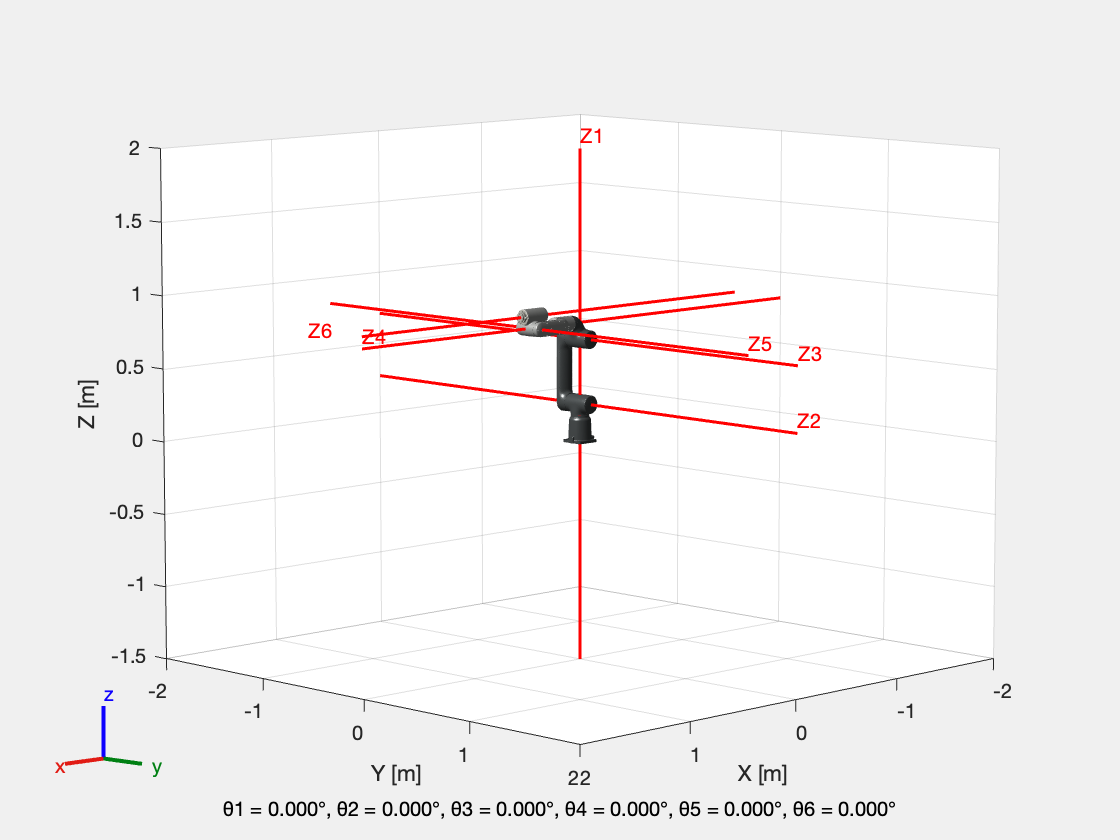


S1 = J(:, 1);
S2 = J(:, 2);
S3 = J(:, 3);
S4 = J(:, 4);
S5 = J(:, 5);
S6 = J(:, 6);

displayRobot(gofa, 'default position',[0, 0, 0, 0, 0, 0], true, T0i)

**S1 S4 (1) and (2)**

- Axis 1 and 4 are coincident

- fully strecth category

Solving the wedge product is null gives 4 cases, 2 of which are in self collision

wedge = wedgeProduct(S1, S4);
sol = solve(wedge == 0, tet2, tet3);

tet2_1 = double(sol.tet2(1));
tet3_1 = double(sol.tet3(1));
q1 = [0, tet2_1, tet3_1, 0, 0, 0];

displayRobot(gofa, 'analysis S1 and S4 (1)', q1, true, T0i);

tet2_2 = double(sol.tet2(2));
tet3_2 = double(sol.tet3(2));
q2 = [0, tet2_2, tet3_2, 0, 0, 0];

displayRobot(gofa, 'analysis S1 and S4 (2)', q2, true, T0i);

**4D joint space**

The singularity is represented by two distinct surfaces where tet2 and tet3 are fixed and tet4 and tet5 are free

- surface 1 is represented by tet2 =  14.344° and tet3 = -104.344°

- surface 2 is represented by tet2 = -165.656° and tet3 = -104.344°

We can easily approximate the area of the surface by

A_14 = 2 * (2*pi) * (2*pi)

**S1 S6 (1)**

- Axis 1 and 6 are coincident

- four cases arise for this singularity

wedge = wedgeProduct(S1, S6);

**1) tet4 = 0° and the end effector is down**

eq1 = 8 + 11 * sin(tet2 + tet3) + 44.4 * sin(tet2) + 47 * cos(tet2 + tet3) == 0; 
eq2 = tet5 == pi/2 - tet3 - tet2 ;

tet2_1 = deg2rad(-30); % free
tet4_1 = 0; % fixed

eq1_fixed = subs(eq1, tet2, tet2_1);
tet3_1 = double(vpasolve(eq1_fixed, tet3));

eq2_fixed = subs(eq2, [tet2, tet3], [tet2_1 tet3_1]);
tet5_1 = double(vpasolve(eq2_fixed, tet5));

q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 and S6 (1)', q1, true, T0i);

**2) tet4 = 0° and the end effector is up**

eq1 = -8 + 11 * sin(tet2 + tet3) + 44.4 * sin(tet2) + 47 * cos(tet2 + tet3) == 0; 
eq2 = tet5 ==  - pi/2 - tet3 - tet2 ;

tet2_1 = deg2rad(-30); % free
tet4_1 = 0; % fixed

eq1_fixed = subs(eq1, tet2, tet2_1);
tet3_1 = double(vpasolve(eq1_fixed, tet3));

eq2_fixed = subs(eq2, [tet2, tet3], [tet2_1 tet3_1]);
tet5_1 = double(vpasolve(eq2_fixed, tet5));

q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 and S6 (2)', q1, true, T0i);

**3) tet4 = 180° and the end effector is down**

eq1 = - 0.08 + 0.11 * sin(tet2 + tet3) + 0.444 * sin(tet2) + 0.47 * cos(tet2 + tet3) == 0; 
eq2 = tet5 ==  - pi/2 + tet3 + tet2 ;

tet2_1 = deg2rad(-30); % free
tet4_1 = deg2rad(180); % fixed

eq1_fixed = subs(eq1, tet2, tet2_1);
tet3_1 = double(vpasolve(eq1_fixed, tet3));

eq2_fixed = subs(eq2, [tet2, tet3], [tet2_1 tet3_1]);
tet5_1 = double(vpasolve(eq2_fixed, tet5));

q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 and S6 (3)', q1, true, T0i);

**4) tet4 = 180° and the end effector is up**

eq1 = 8 + 11 * sin(tet2 + tet3) + 44.4 * sin(tet2) + 47 * cos(tet2 + tet3) == 0; 
eq2 = tet5 ==  pi/2 + tet3 + tet2 ;

tet2_1 = deg2rad(-30); % free
tet4_1 = deg2rad(180); % fixed

eq1_fixed = subs(eq1, tet2, tet2_1);
tet3_1 = double(vpasolve(eq1_fixed, tet3));

eq2_fixed = subs(eq2, [tet2, tet3], [tet2_1 tet3_1]);
tet5_1 = double(vpasolve(eq2_fixed, tet5));

q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 and S6 (4)', q1, true, T0i);

**4D joint space**

This singularity is represented by four lines which are the same for each equation

z = @(tet2, tet3) 0.08 + 0.11 * sin(tet2 + tet3) + 0.444 * sin(tet2) + 0.47 * cos(tet2 + tet3);

range2 = linspace(-pi, pi, 500);
range3 = linspace(deg2rad(-225), deg2rad(65), 500);

[TET2, TET3] = meshgrid(range2, range3);

Z = z(TET2, TET3);

figure;
[C, h] = contour(TET2, TET3, Z, [0 0], 'LineWidth', 1, 'LineColor', [0.1 0.1 0.1]);
xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
title('line S1 S6');
grid on;

saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/line_S1_S6.fig');

Evaluate the lenght

L_16 = 4*(2.67 + 3.14 + 5.81);

Unrecognized function or variable 'C'.

**S1 S4 S5**

- axes 1, 4 and 5 are coplanar and concurrent

- two cases arise: tet4 = -90° or tet4 = 90°

**Note**: it's almost the same equation as S1 S6 without the 8 constant

wedge = wedgeProduct(S1, S4, S5);
w1 = vpa(simplify(subs(wedge, tet4, -pi/2)));
w2 = vpa(simplify(subs(wedge, tet4,  pi/2)));

**1) tet4 = -90°**

eq = w1(6);

tet2_1 = deg2rad(-30); % free
tet4_1 = deg2rad(-90); % fixed
tet5_1 = deg2rad(0); % free 

eq_fixed = subs(eq, tet2, tet2_1);
tet3_1 = double(vpasolve(eq_fixed, tet3));

q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 S4 and S5 (1)', q1, true, T0i);

**1) tet4 = 90°**

eq = w2(6);

tet2_2 = deg2rad(-30); % free
tet4_2 = deg2rad(90); % fixed
tet5_2 = deg2rad(0); % free 

eq_fixed = subs(eq, tet2, tet2_1);
tet3_2 = double(vpasolve(eq_fixed, tet3));

q2 = [0, tet2_2, tet3_2, tet4_2, tet5_2, 0];
displayRobot(gofa, 'analysis S1 S4 and S5 (2)', q2, true, T0i);

**4D joint space**

This singularity is represented by two surfaces for tet4 = -90° and tet4 = 90°. The two cases have the same equation

z = @(tet2, tet3) 11 * sin(tet2 + tet3) + 44.4 * sin(tet2) + 47 * cos(tet2 + tet3);

range2 = linspace(-pi, pi, 500);
range3 = linspace(deg2rad(-225), deg2rad(65), 500);

[TET2, TET3] = meshgrid(range2, range3);

Z = z(TET2, TET3);

figure;
[C, ~] = contour(TET2, TET3, Z, [0 0], 'LineWidth', 1, 'LineColor', 'k');
xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
title('line S1 S4 S5');
grid on;
hold on;

saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/line_S1_S4_S5.fig');

figure;
title('surface S1 S4 S5');

idx = 1;
while idx < size(C,2)
    level = C(1,idx);
    n_points = C(2,idx);
    pts = C(:, idx+1:idx+n_points);
    idx = idx + n_points + 1;

    tet5_range = linspace(-pi, pi, 100);
    [TET5, ~] = meshgrid(tet5_range, 1:n_points);

    tet2_extrude = repmat(pts(1,:)', 1, length(tet5_range));
    tet3_extrude = repmat(pts(2,:)', 1, length(tet5_range));
    tet5_extrude = TET5;

    surf(tet2_extrude, tet3_extrude, tet5_extrude, ...
         'EdgeColor', 'none');
    grid on;
    hold on;
end

xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
zlabel('\theta_5 [rad]');
view(3);

saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/surface_S1_S4_S5.fig');

Evaluate the total area

A_145 = 145; % rad^2

**S1 S4 S6**

- axes 1, 4 and 6 are coplanar and parallel

- axes 1, 4 and 6 are coplanar and concurrent

wedge = wedgeProduct(S1, S4, S6);
w = vpa(simplify(subs(wedge, tet4, 0))); % condition to have axes 1, 4 and 6 coplanar

**axes 1, 4 and 6 are coplanar and parallel**

This case is possible for 8 different combination of the following variables:

- tet2 + tet3 = 90° or 90°+180°

- tet4 = 0° or 180°

- tet5 = 0° or 180°

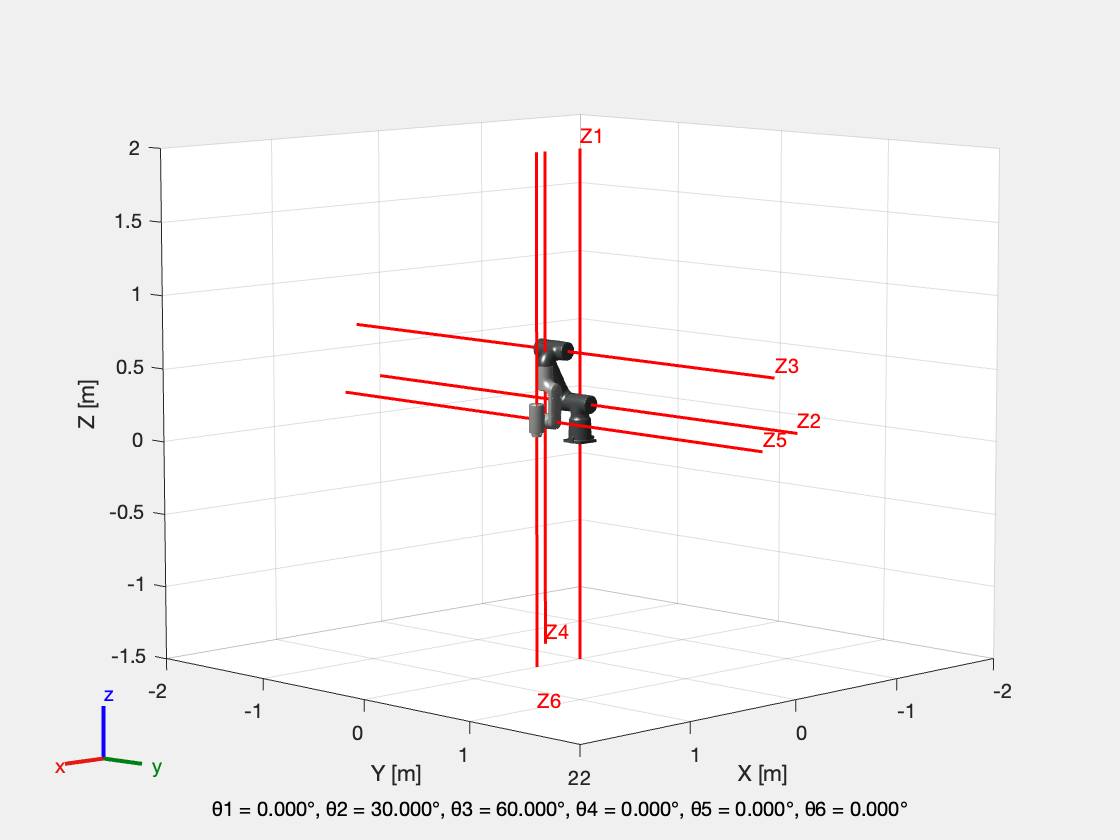

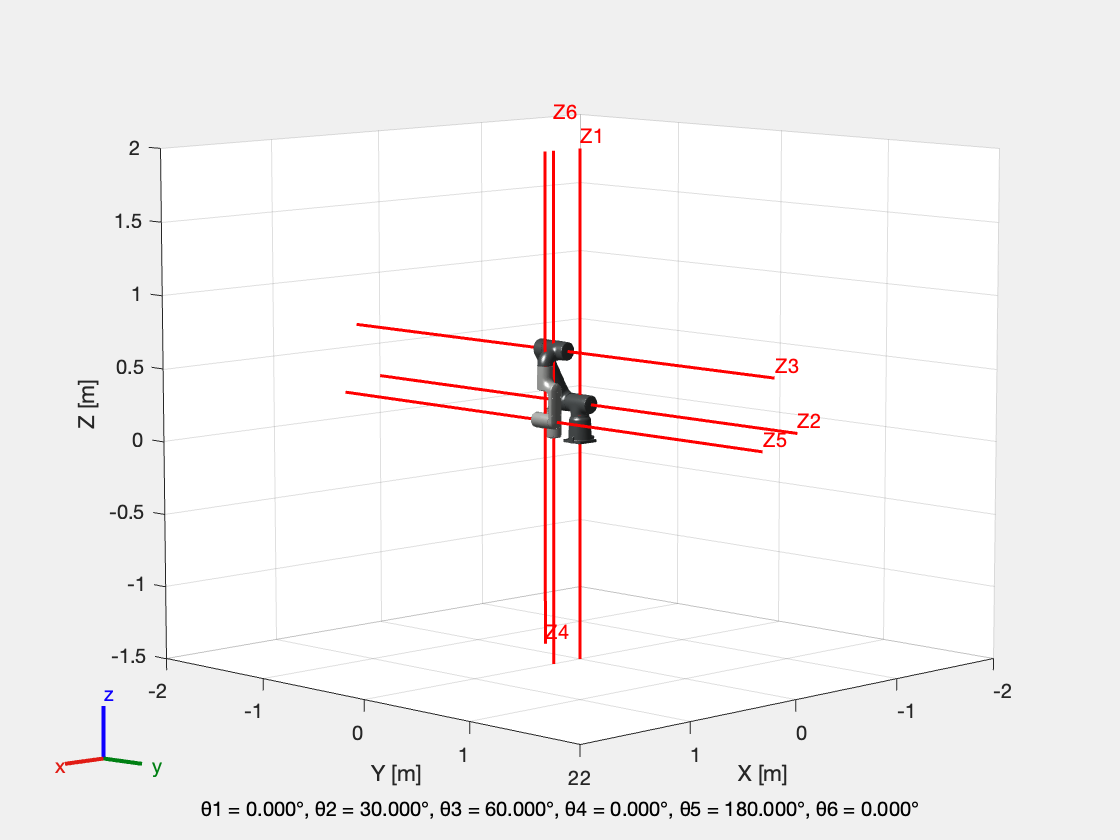

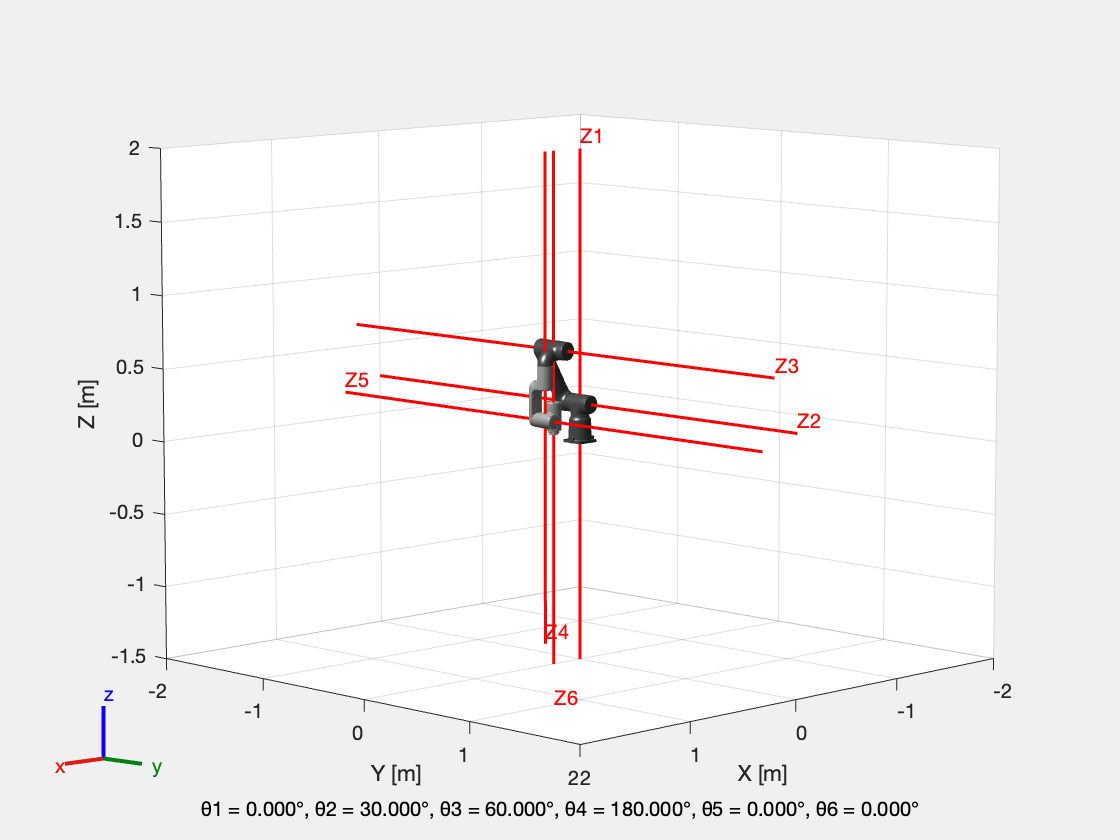

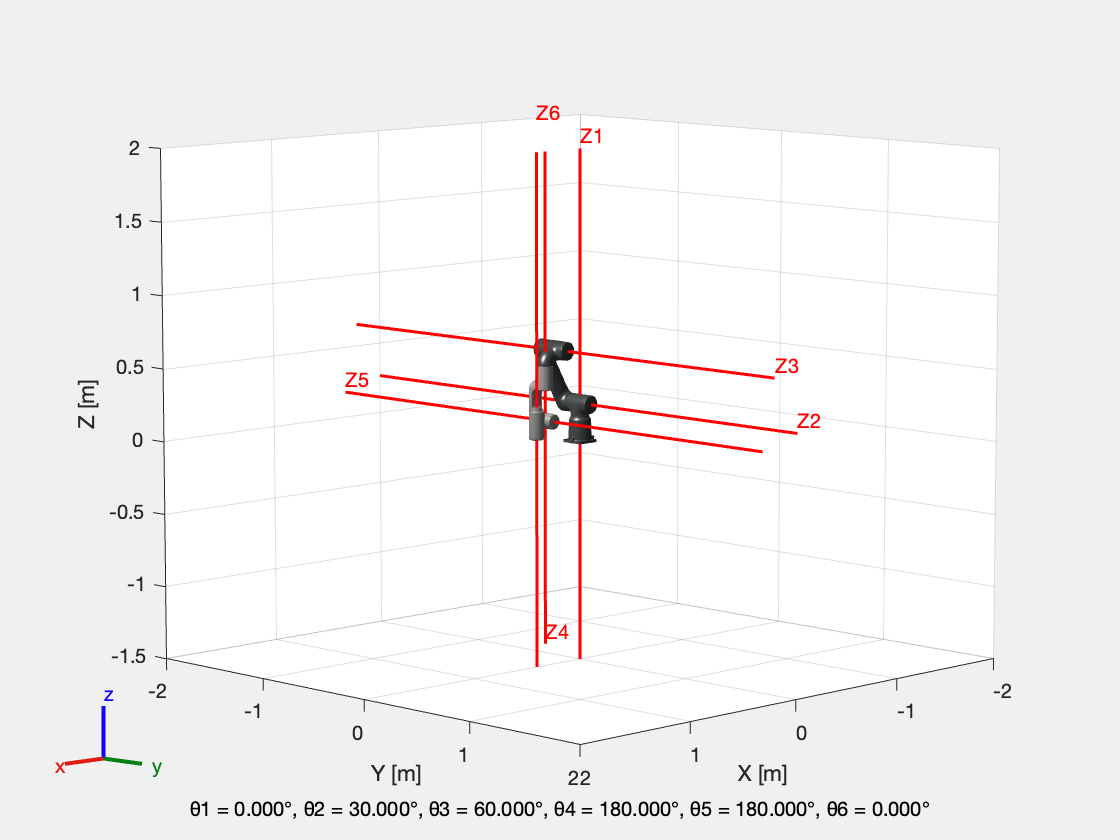

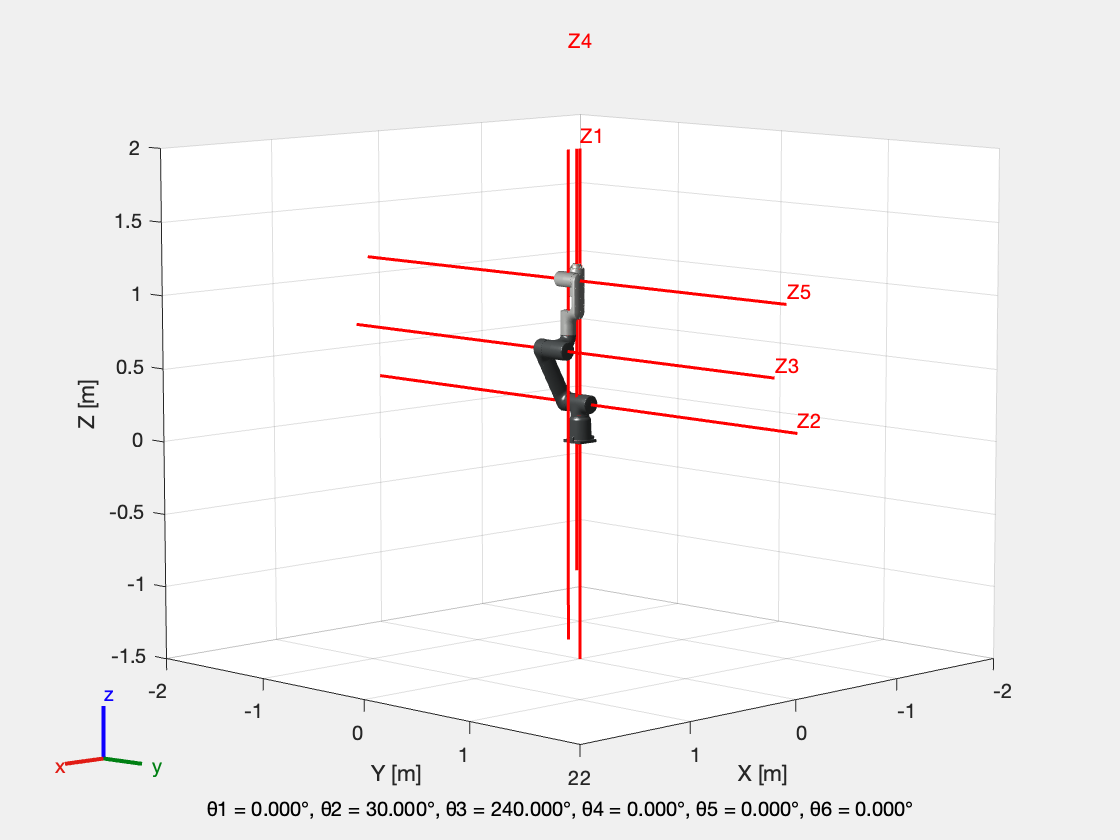

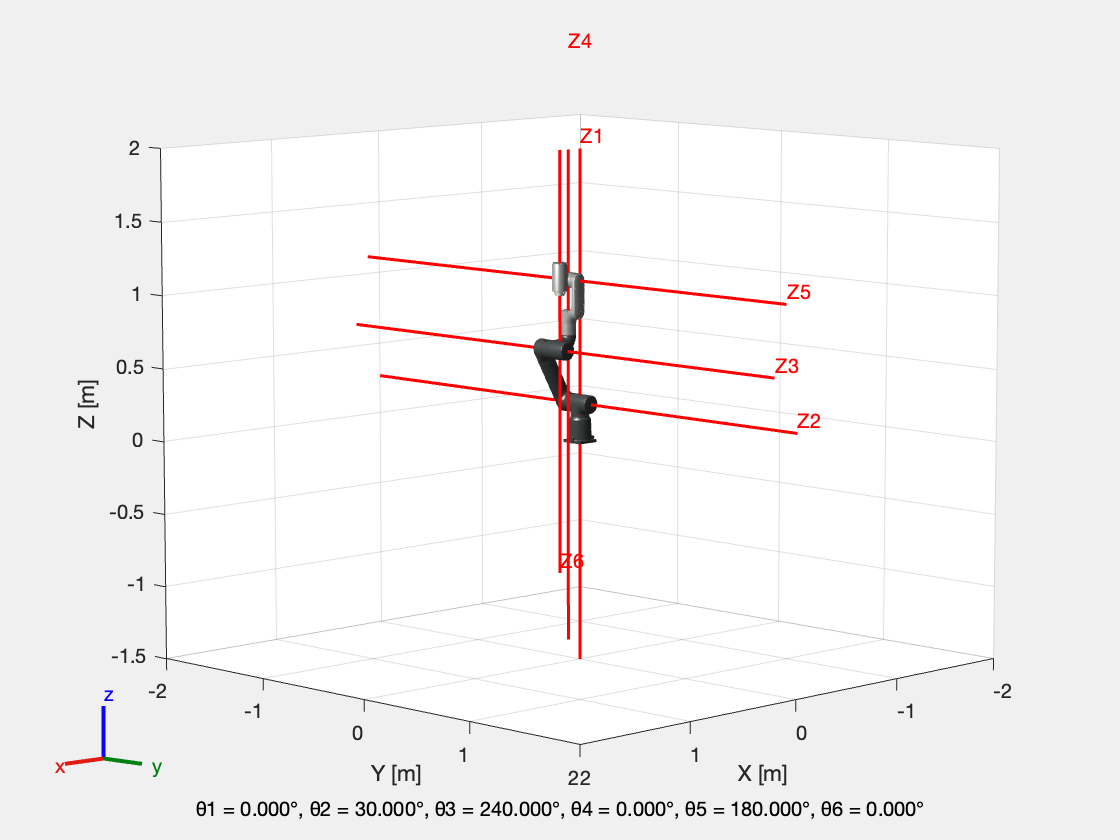

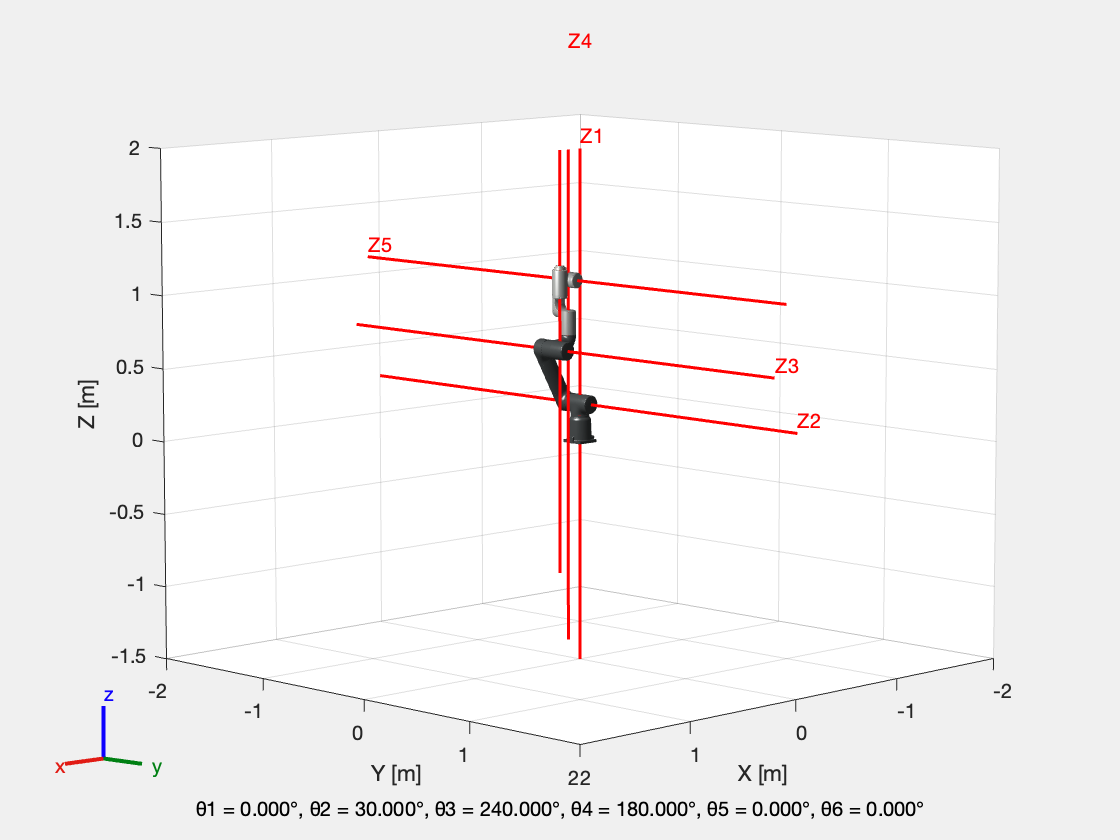

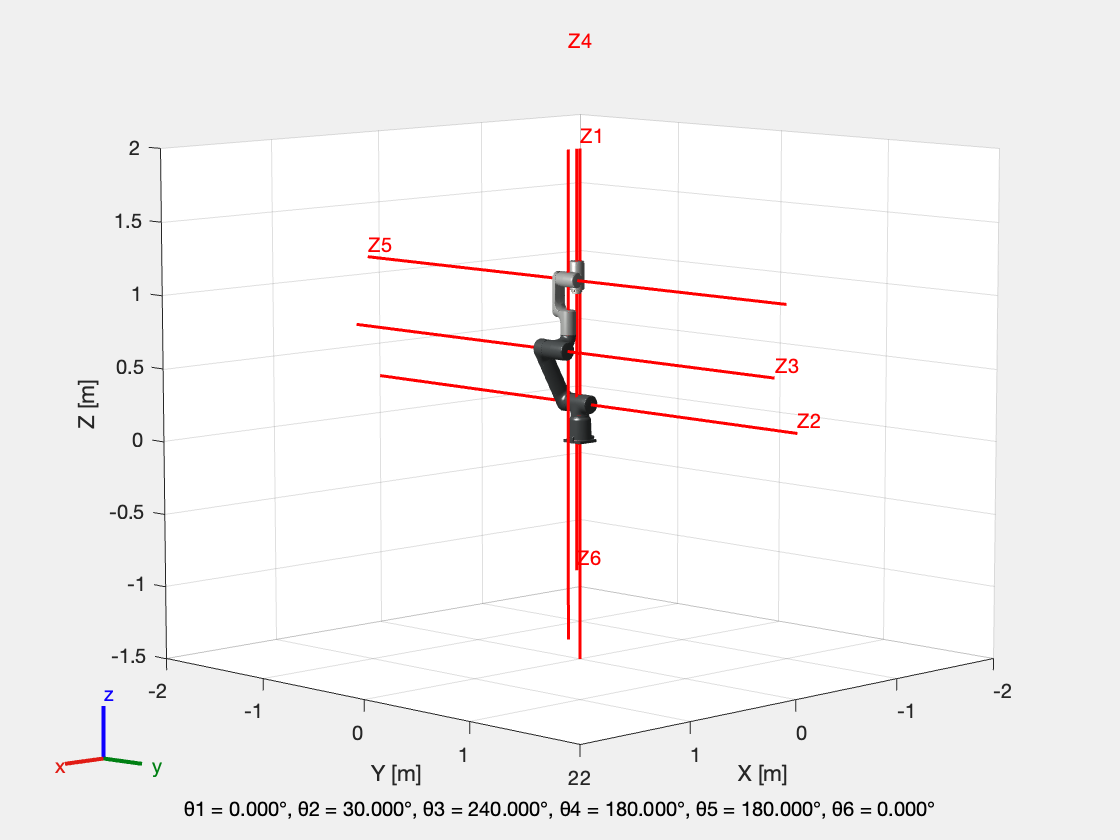

tet2_val = 30; % free

q_deg = [
    0,  tet2_val,  90 - tet2_val,  0,    0,    0;
    0,  tet2_val,  90 - tet2_val,  0,    180,  0;
    0,  tet2_val,  90 - tet2_val,  180,  0,    0;
    0,  tet2_val,  90 - tet2_val,  180,  180,  0;
    0,  tet2_val,  270 - tet2_val, 0,    0,    0;
    0,  tet2_val,  270 - tet2_val, 0,    180,  0;
    0,  tet2_val,  270 - tet2_val, 180,  0,    0;
    0,  tet2_val,  270 - tet2_val, 180,  180,  0;
];

for i = 1:size(q_deg, 1)
    qi_rad = deg2rad(q_deg(i, :));
    displayRobot(gofa, sprintf('analysis S1 S4 S6 (%d)', i), qi_rad, true, T0i);
end

**4D joint space** this singularity represent 8 lines, where tet2 is free

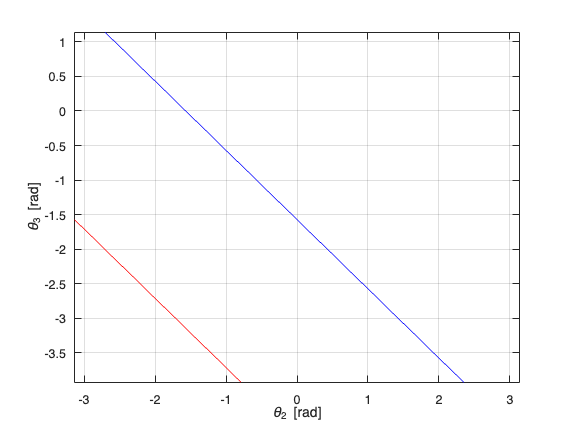

tet2_1 = linspace(-pi, pi, 500);

tet3_1 = pi/2 - tet2_1 -2*pi;
tet3_2 = 3*pi/2 - tet2_1 -2*pi;

figure;
plot(tet2_1, tet3_1, 'r'); hold on;
plot(tet2_1, tet3_2, 'b');

xlim([-pi pi]);
ylim([deg2rad(-225) deg2rad(65)]);

xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
grid on;


saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/line_S1_S4_S6.fig');

**axes 1, 4 and 6 are coplanar and concurrent**

There are no easy condition to describe it rather than the previous equation or the floowing equation

eq = ...
+ 5.37   * cos(tet2) * sin(tet5) ...
- 3.91   * sin(tet2) ...
- 22.95  * sin(tet2) * sin(tet5) ...
+ 16.69  * cos(tet2) * cos(tet3)^2 ...
+ 3.91   * cos(tet3)^2 * sin(tet2) ...
- 16.69  * cos(tet3) * sin(tet2) * sin(tet3) ...
+ 92.65  * cos(tet3) * sin(tet2) * sin(tet5) ...
+ 21.68  * sin(tet2) * sin(tet3) * sin(tet5) ...
+ 92.71  * cos(tet2) * cos(tet3)^2 * sin(tet5) ...
+ 45.91  * cos(tet3)^2 * sin(tet2) * sin(tet5) ...
+ 3.91   * cos(tet2) * cos(tet3) * sin(tet3) ...
+ 45.91  * cos(tet2) * cos(tet3) * sin(tet3) * sin(tet5) ...
- 92.71  * cos(tet3) * sin(tet2) * sin(tet3) * sin(tet5) == 0;


tet2_1 = deg2rad(10); % free
tet3_1 = deg2rad(10); %free
tet4_1 = 0; % or pi fixed

eq = subs(eq, [tet3 tet2], [tet3_1 tet2_1]);

sol = vpasolve(eq == 0, tet5)

$$sol = -0.1354992838000764576808951224282$$

tet5_1 = double(sol)

tet5_1 = -0.1355

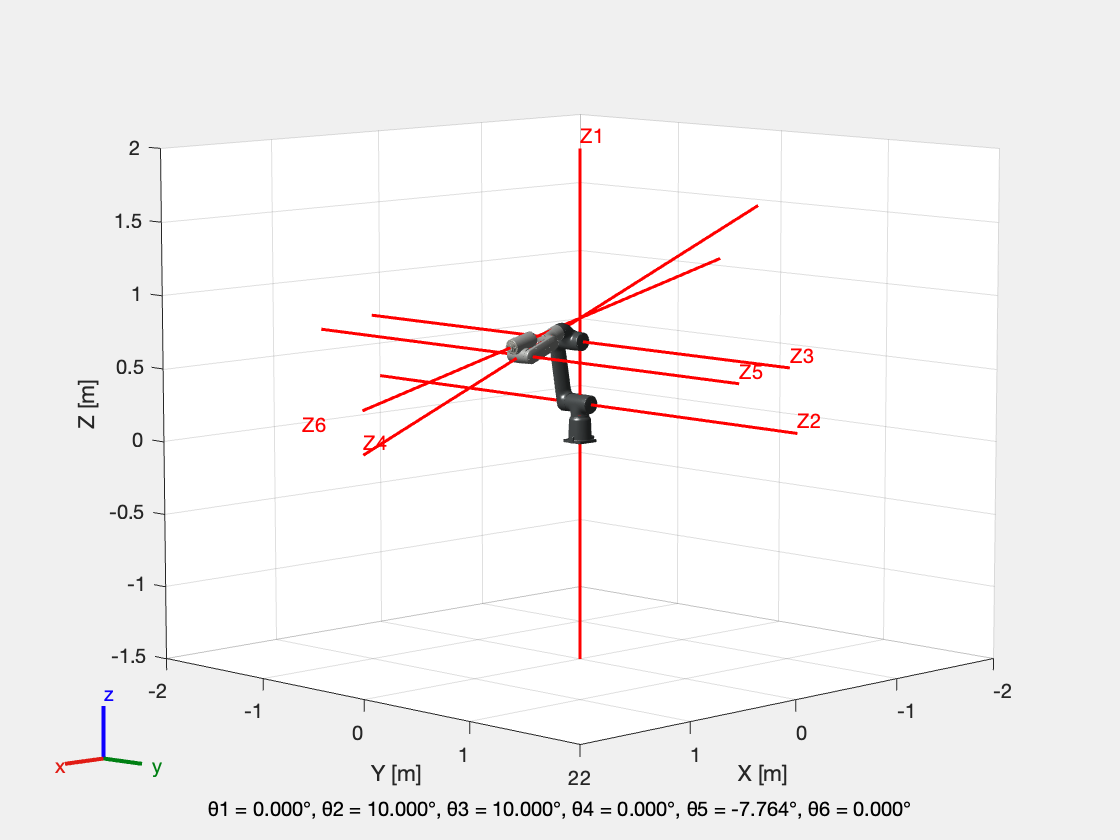


q1 = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S4 and S6 (9)',q1, true, T0i)

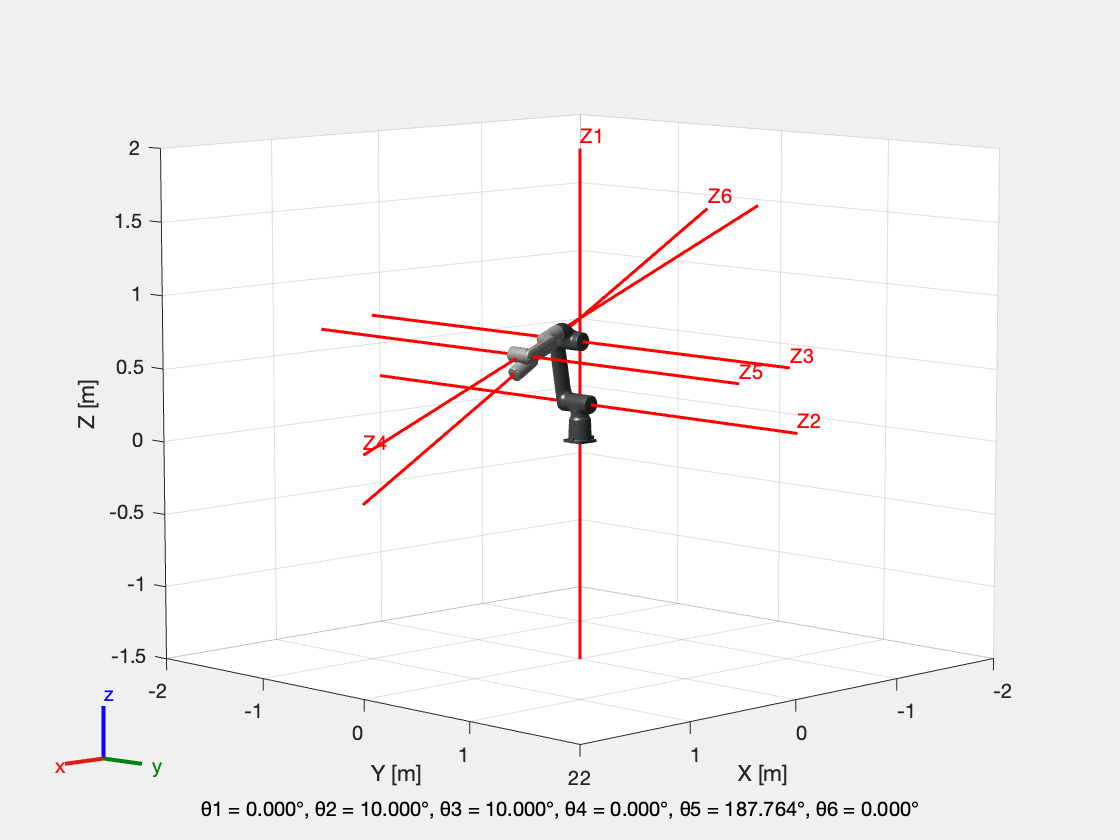


q2 = [0, tet2_1, tet3_1, tet4_1, pi-tet5_1, 0];
displayRobot(gofa, 'analysis S1, S4 and S6 (10)',q2, true, T0i)

**4D joint space** this singularity represent 2 surfaces where tet2 and tet3 are free

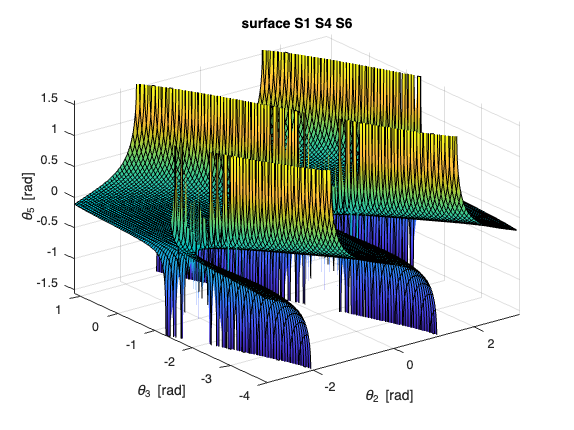

tet5_1 = @(tet2, tet3) arrayfun(@(t2, t3) ...
    asin( -0.08 * cos(t2 + t3) / ...
         (0.11 * sin(t2 + t3) + 0.444 * sin(t2) + 0.47 * cos(t2 + t3)) ), ...
    tet2, tet3);

figure;
fsurf(tet5_1, [-pi pi deg2rad(-225) deg2rad(65)], 'MeshDensity', 100);
xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
zlabel('\theta_5 [rad]');
title('surface S1 S4 S6');
grid on;
view(3);


saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/surface_S1_S4_S6.fig');

Evaluate the area of one surface

A_146 = 2*56 % 112rad^2

A_146 = 112

**S2, S3 and S5**

axes 2, 3 and 5 are coplanar and parallel. When tet4 = 0° or 180° and tet3 = -76.83°

wedge = wedgeProduct(S2, S3, S5);

w = vpa(simplify(subs(wedge, tet4, 0)));
w = vpa(simplify(subs(wedge, tet4, pi)));

tet2_1 = deg2rad(-30);
tet4_1 = deg2rad(0);

eq = w(15);
sol = vpasolve(eq == 0, tet3, [deg2rad(-225), deg2rad(65)]);
tet3_1 = double(sol);

q1 = [0, tet2_1, tet3_1, tet4_1, 0, 0];
displayRobot(gofa, 'analysis S2, S3 and S5 (1)',q1, true, T0i)

tet4_1 = deg2rad(180)

q2 = [0, tet2_1, tet3_1, tet4_1, 0, 0];
displayRobot(gofa, 'analysis S2, S3 and S5 (2)',q2, true, T0i)

**4D joint space**, two surfaces for tet4 = 0° and tet4 = 180°

A_235 = 2*(2*pi)^2 %78.96rad^2

**S2 S3 and S6**

axes 2, 3 and 6 are coplanar and parallel. 

4 cases arise:

- tet3 = -74.25°, tet4 = -90°, tet5 = -90°

- tet3 = -78.69°, tet4 = -90°, tet5 = 90°

- tet3 = -74.25°, tet4 = 90°, tet5 = -90°

- tet3 = -78.69°, tet4 = 90°, tet5 = 90°

where tet2 is free

wedge = wedgeProduct(S2, S3, S6);

w = vpa(simplify(subs(wedge, tet4, pi/2)));
w = vpa(simplify(subs(w, tet5, pi/2)));

tet2_1 = -30; % free

q_deg = [
    0,  tet2_1,  0, -90, -90,  0;
    0,  tet2_1,  0, -90,  90,  0;
    0,  tet2_1,  0,  90, -90,  0;
    0,  tet2_1,  0,  90,  90,  0;
];

for i = 1:size(q_deg, 1)

    eq = simplify(subs(wedge, tet4, deg2rad(q_deg(i, 4))));
    eq = simplify(subs(eq, tet5, deg2rad(q_deg(i, 5))));

    sol = vpasolve(eq == 0, tet3, [deg2rad(-225), deg2rad(65)]);
    tet3_1 = rad2deg(double(sol));

    qi_deg = [0, q_deg(i, 2), tet3_1, q_deg(i, 4), q_deg(i, 5), 0];
    qi_rad = deg2rad(qi_deg);

    displayRobot(gofa, sprintf('analysis S1 S4 and S6 (%d)', i), qi_rad, true, T0i);
end

**4D joint space**, four lines for all the combinations

L_236 = 4*2*pi; % 25.23rad^2

**S2 S4 and S6**

this singularity is a special case of the larger singularity **S1, S2, S4 and S6**

wedge = wedgeProduct(S1, S2, S4, S6);

Equations to have axis 1, 2 and 4 coincident in the same point

eq1 = 222*cos(tet3) + 55;
tet3_1 = double(vpasolve(eq1 == 0, tet3, [deg2rad(-225), deg2rad(65)]));

w = vpa(simplify((subs(wedge, tet3, tet3_1))));

Equations to have axis 1, 2 and 5 coincident in the same point

eq2 = 450.07906*sin(tet5) + 40;
tet5_1 = double(vpasolve(eq2 == 0, tet5, [-pi, pi]));

tet2_1 = -30;
tet4_1 = -30;

q = [0, deg2rad(tet2_1), tet3_1, deg2rad(tet4_1), tet5_1, 0];
displayRobot(gofa, sprintf('analysis S1 S2 S4 and S6 (1)', i), q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));
vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));

q = [0, deg2rad(tet2_1), tet3_1, deg2rad(tet4_1), pi - tet5_1, 0];
displayRobot(gofa, sprintf('analysis S1 S2 S4 and S6 (2)', i), q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));
vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));

**S1, S2, S3 and S6**

Axes 1, 2, 3, 6 can be coplanar

this singularity is completely included in the larger singularity **S1, S2, S3, S4 and S6 **

in the joint space the singularity **S2 S3 S6** and **S1 S2 S3 S6** intersect

wedge = vpa(wedgeProduct(S1, S2, S3, S6));
w = vpa(simplify(subs(wedge, tet2, 0)));

**first** set of equations to have axes 1, 2, 3 and 6 coplanar

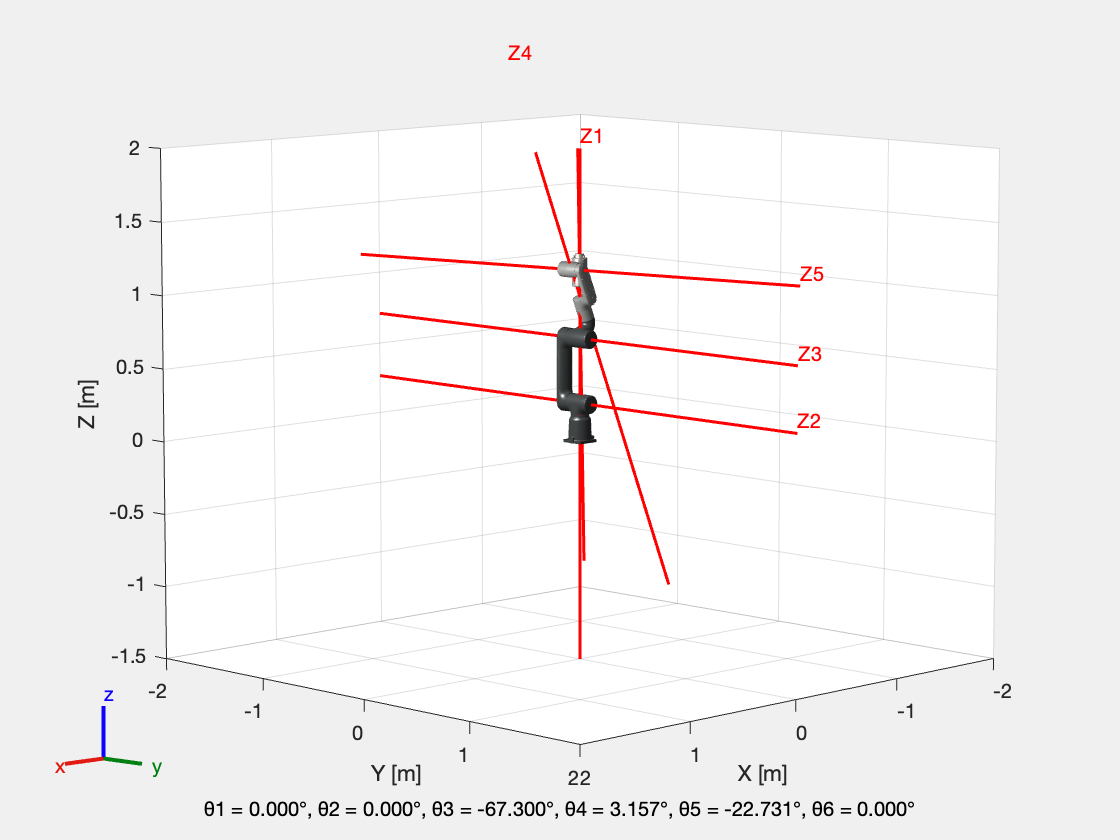

eq1 = 8.0*cos(tet3) + 47.0*cos(tet3)*sin(tet5) + 11.0*sin(tet3)*sin(tet5);
eq2 = 8.0*cos(tet4) + 11.0*cos(tet5) + 47.0*cos(tet4)*sin(tet5);
% the system is slovable for certain values of tet3 and tet4 
% can also be -tet4 as cos(x) = cos(-x)

% tet3 goes from -67.2877 to -86.36725
tet3_1 = deg2rad(-67.3); % tet3 is bound to certain values 
% 77° and 78° doesn't work
eq1 = subs(eq1, tet3, tet3_1);

sol = vpasolve(eq1 == 0, eq2 == 0, [tet4, tet5], [-pi, pi; -pi, pi]);

tet4_1 = double(sol.tet4);
tet5_1 = double(sol.tet5);

q = [0, 0, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 S2 S3 and S6 (1)', q, true, T0i);

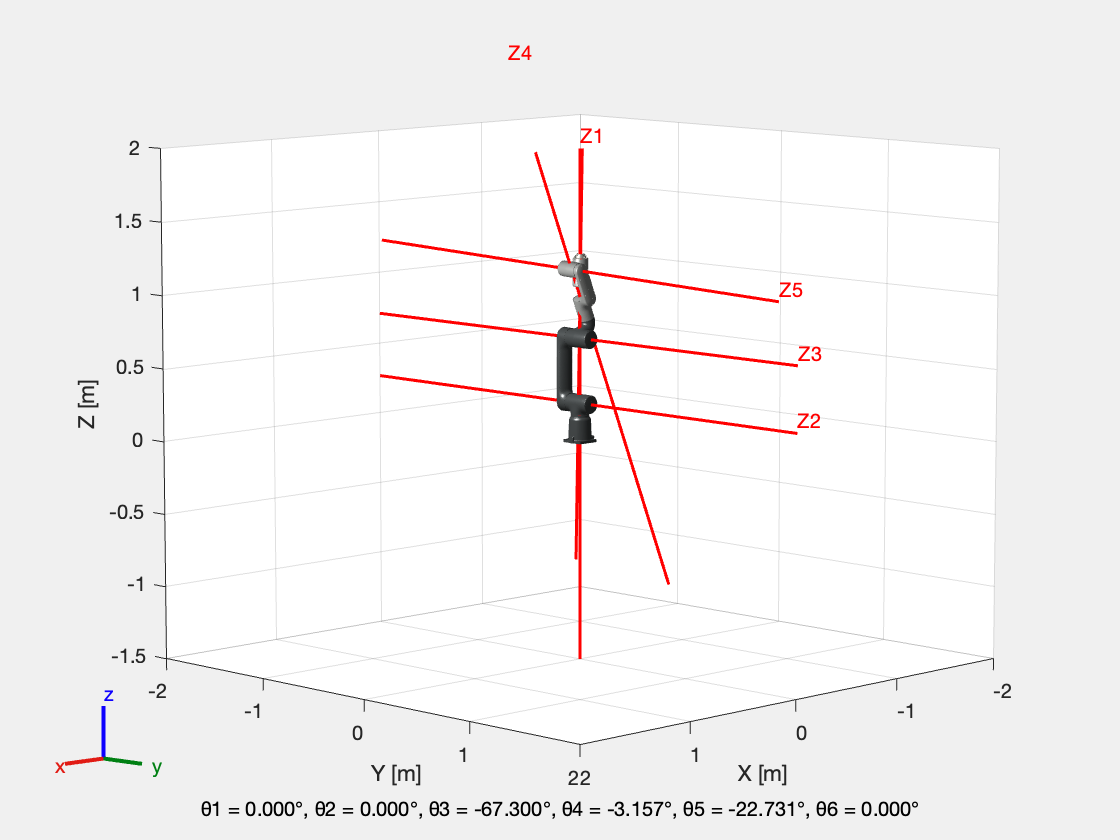


q = [0, 0, tet3_1, -tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1 S2 S3 and S6 (2)', q, true, T0i);


vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));

**second** set of equations to have axes 1, 2, 3 and 6 coplanar

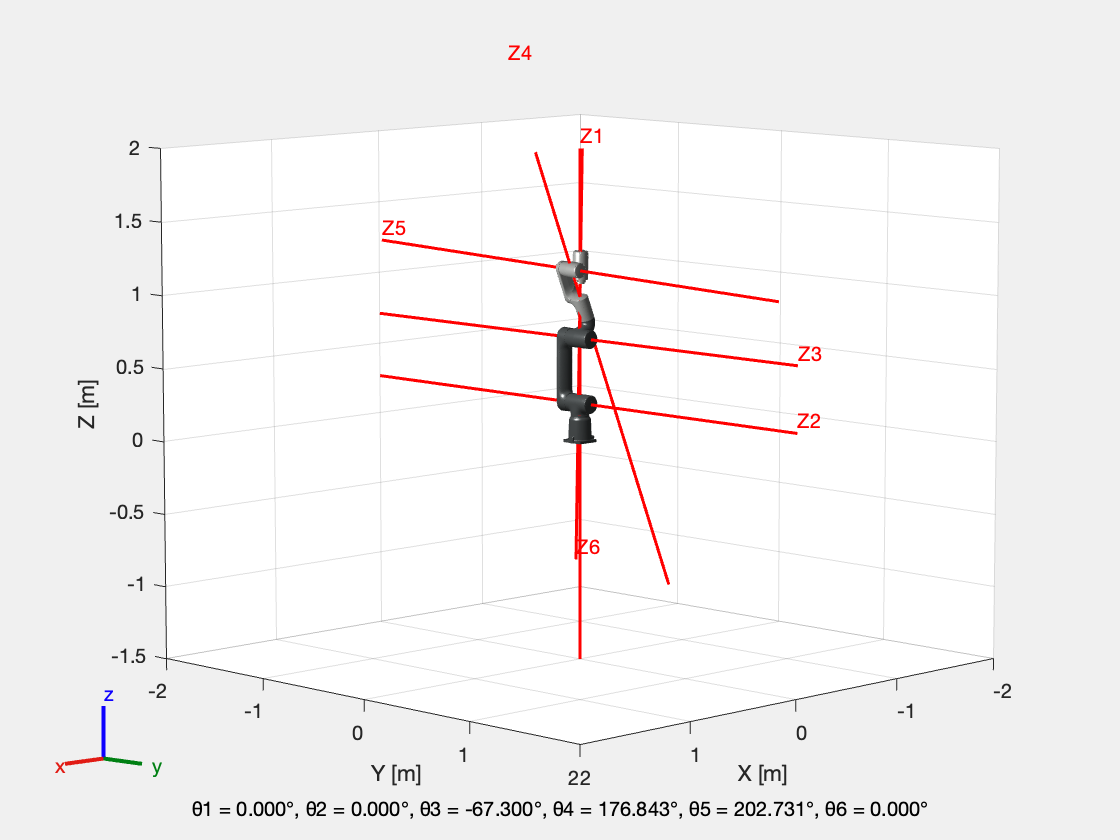

eq1 = -8.0*cos(tet3) + sin(tet5)*(47.0*cos(tet3) + 11.0*sin(tet3));
eq2 = -8.0*cos(tet4) + 47.0*cos(tet4)*sin(tet5) + 11.0*cos(tet5);
% the system is slovable for certain values of tet3 and tet4 can also be
% -tet4 as this is only in cos

% tet3 goes from -67.2877 to -86.36725
tet3_2 = deg2rad(-67.3); % tet3 is bound to certain values
eq1 = subs(eq1, tet3, tet3_2);

sol = vpasolve(eq1 == 0, eq2 == 0, [tet4, tet5], [-pi, pi; -pi, pi]);

tet4_2 = double(sol.tet4);
tet5_2 = double(sol.tet5);

q = [0, 0, tet3_2, tet4_2, tet5_2+pi, 0];
displayRobot(gofa, 'analysis S1 S2 S3 and S6 (3)', q, true, T0i);

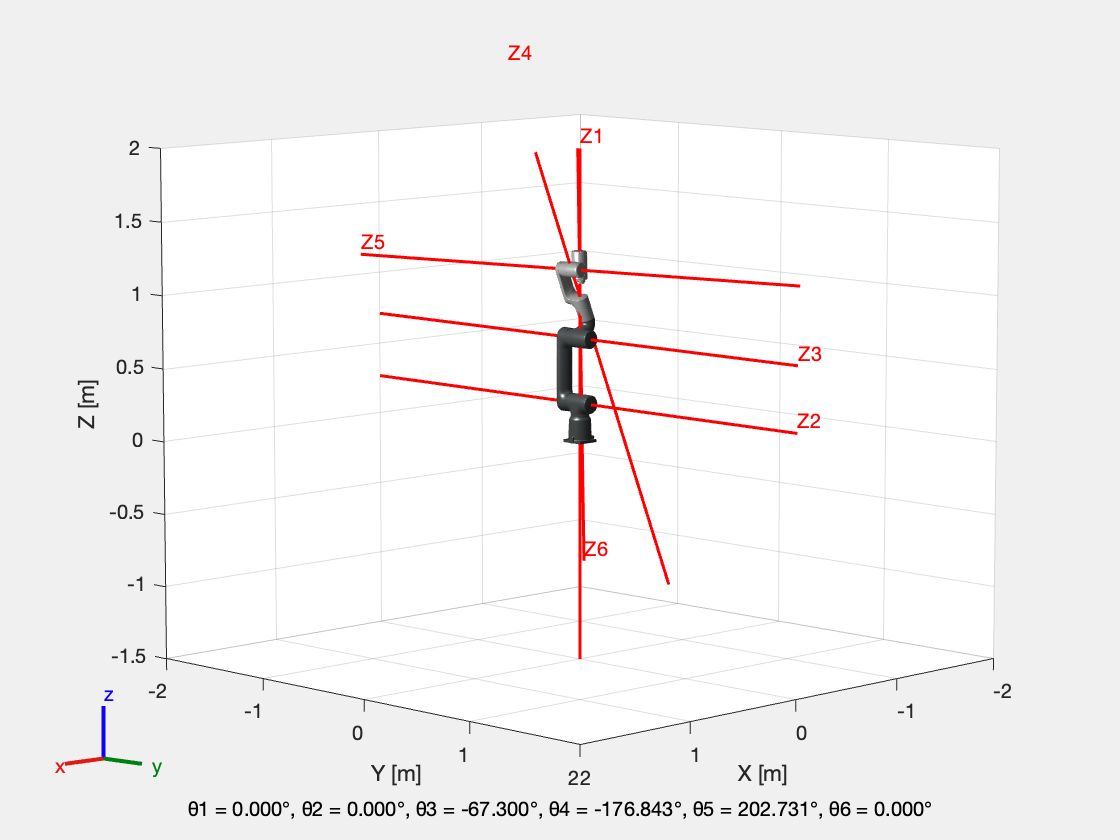


q = [0, 0, tet3_2, -tet4_2, tet5_2+pi, 0];
displayRobot(gofa, 'analysis S1 S2 S3 and S6 (4)', q, true, T0i);


vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));
vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]));
% 0, 0, -86.367, 0.238, 176.367,0

**S1, S2, S3, S4, and S5**

Axes 1, 2, 3, 4 and 5 are lying in two planes (axes 1, 2 and 3 in one plane and axes 4 and 5 in another)  and all the axes intersect the line of intersection of the two planes (not sure about the interpretation, not really explained, condition c1 of the document)

wedge = vpa(simplify(wedgeProduct(S1, S2, S3, S4, S5)))
tet4_1 = deg2rad(30); % free
tet5_1 = deg2rad(30); % free

eq1 = 235*cos(tet2+tet3)+55*sin(tet2+tet3)+222*sin(tet2);
eq2 = 47*cos(tet3)+11*sin(tet3)

sol = vpasolve([eq1 == 0, eq2 == 0], [tet2, tet3], [-pi, pi; deg2rad(-225), deg2rad(65)]);
tet2_1 = double(sol.tet2);
tet3_1 = double(sol.tet3);

q = [0, tet2_1 + 2*pi, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4 and S5 (1)',q, true, T0i);

q = [0, tet2_1 + pi, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4 and S5 (2)',q, true, T0i);

**S1, S2, S3, S4, and S6**

This singularity includes two different gemoetrical conditions:

- Axes 1, 2, 3, 4 and 6 are lying in two planes (axes 1, 2 and 3 in one plane and axes 4 and 6 in another) and all the axes intersect the line of intersection of the two planes (not sure about the interpretation, not really explained, condition c1 of the document). Include the previous singularity **S1, S2, S3 and S6 **

- Axes 1, 2, 3, 4 and 6 are normal and intersect a common line

**Axes 1, 2, 3, 4 and 6 are lying in two planes**

wedge = vpa(wedgeProduct(S1, S2, S3, S4, S6));
w = vpa(simplify(subs(wedge, tet2, 0)))

$$w = \begin{array}{l} \left(\begin{array}{c} 0.00444\,\cos\left({\mathrm{tet}}_{4}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sigma_{1}\\ 0.00444\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{4}\right)\,\sigma_{1}\\ -0.00444\,\cos\left({\mathrm{tet}}_{3}\right)\,\cos\left({\mathrm{tet}}_{4}\right)\,\sigma_{1}\\ 0\\ 0.0004884\,\cos\left({\mathrm{tet}}_{4}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sigma_{1}\\ 0.0004884\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{4}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8.0\,\cos\left({\mathrm{tet}}_{3}\right)+47.0\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+11.0\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right) \end{array}$$

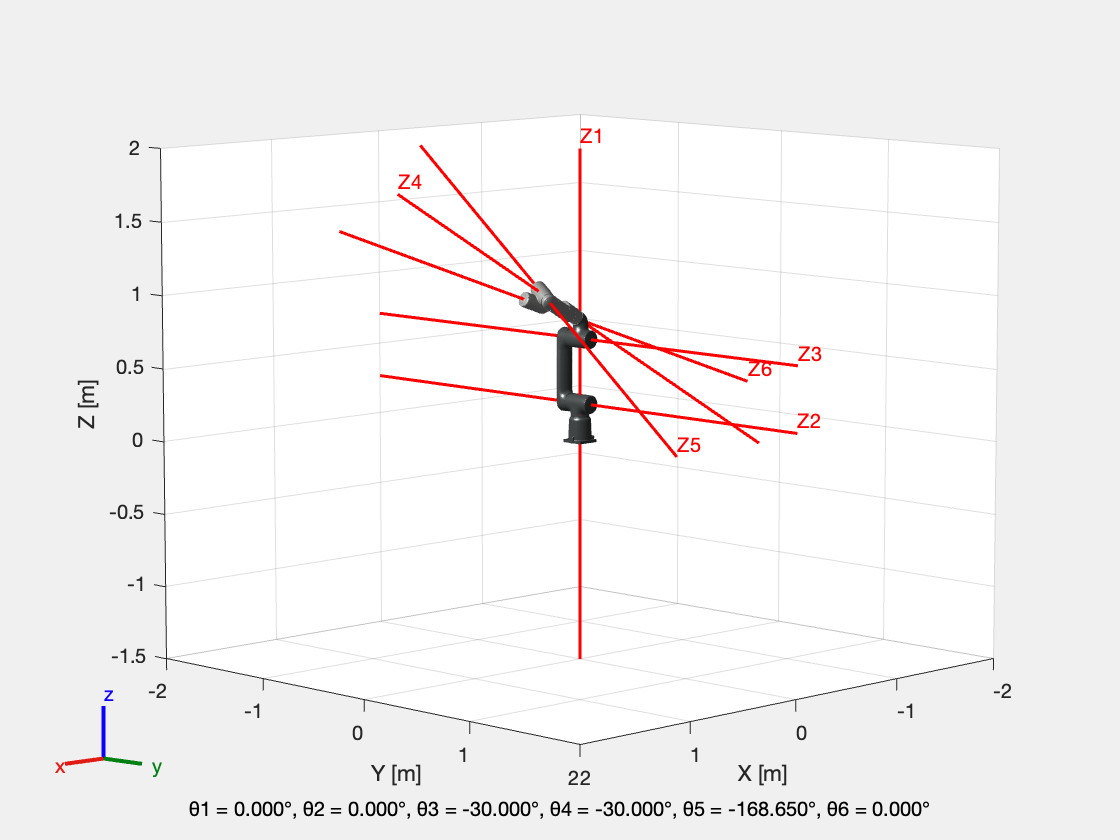


eq = 8*cos(tet3)+sin(tet5)*(47*cos(tet3)+11*sin(tet3));

tet2_1 = deg2rad(0); % or 180° fixed 
tet3_1 = deg2rad(-30); % free
tet4_1 = deg2rad(-30); % free

eq = subs(eq, tet3, tet3_1);
sol = vpasolve(eq == 0, tet5, [-pi, pi]);

tet5_1 = double(sol);

q = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (1)', q, true, T0i);

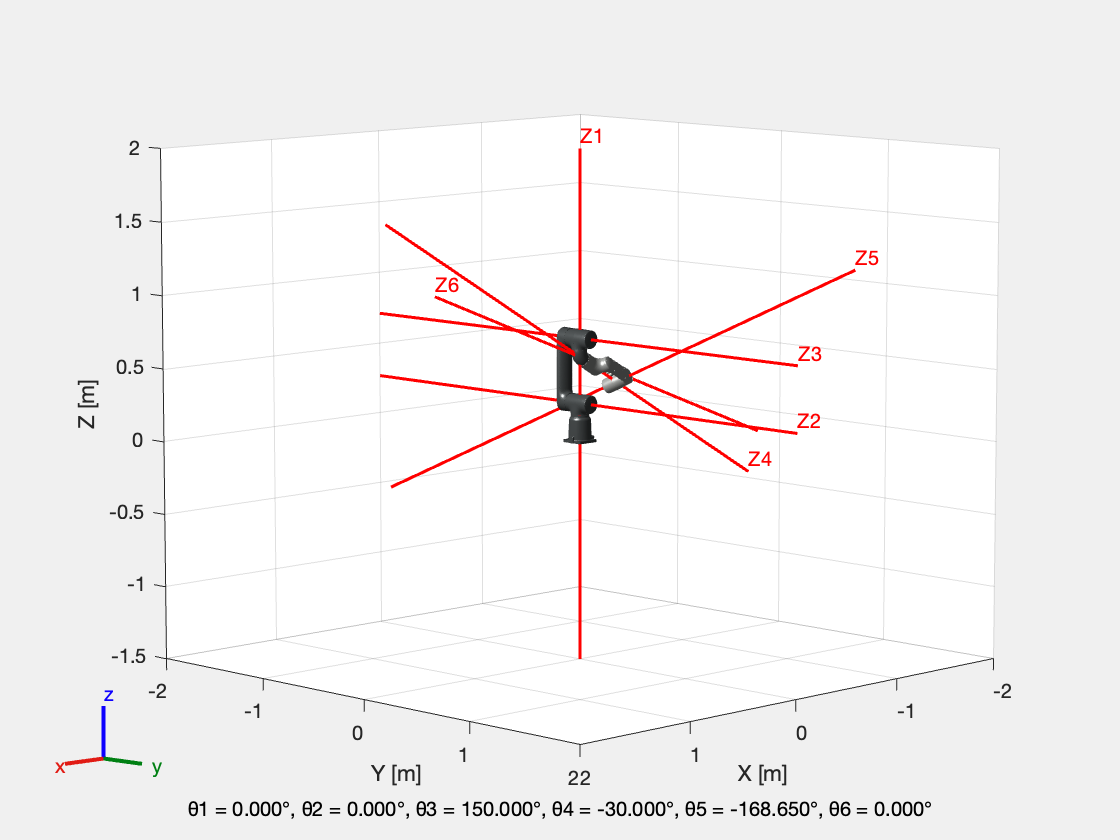


q = [0, tet2_1, tet3_1+pi, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (2)', q, true, T0i);

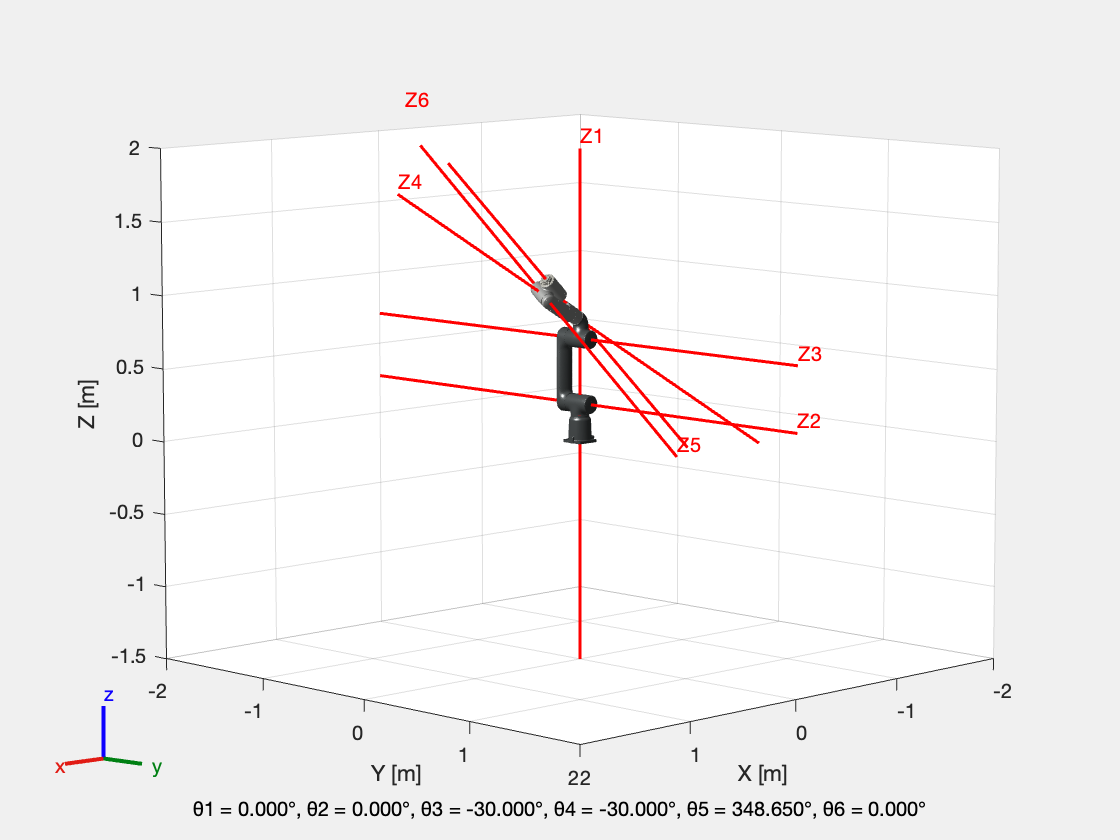


q = [0, tet2_1, tet3_1, tet4_1, pi-tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (3)', q, true, T0i);

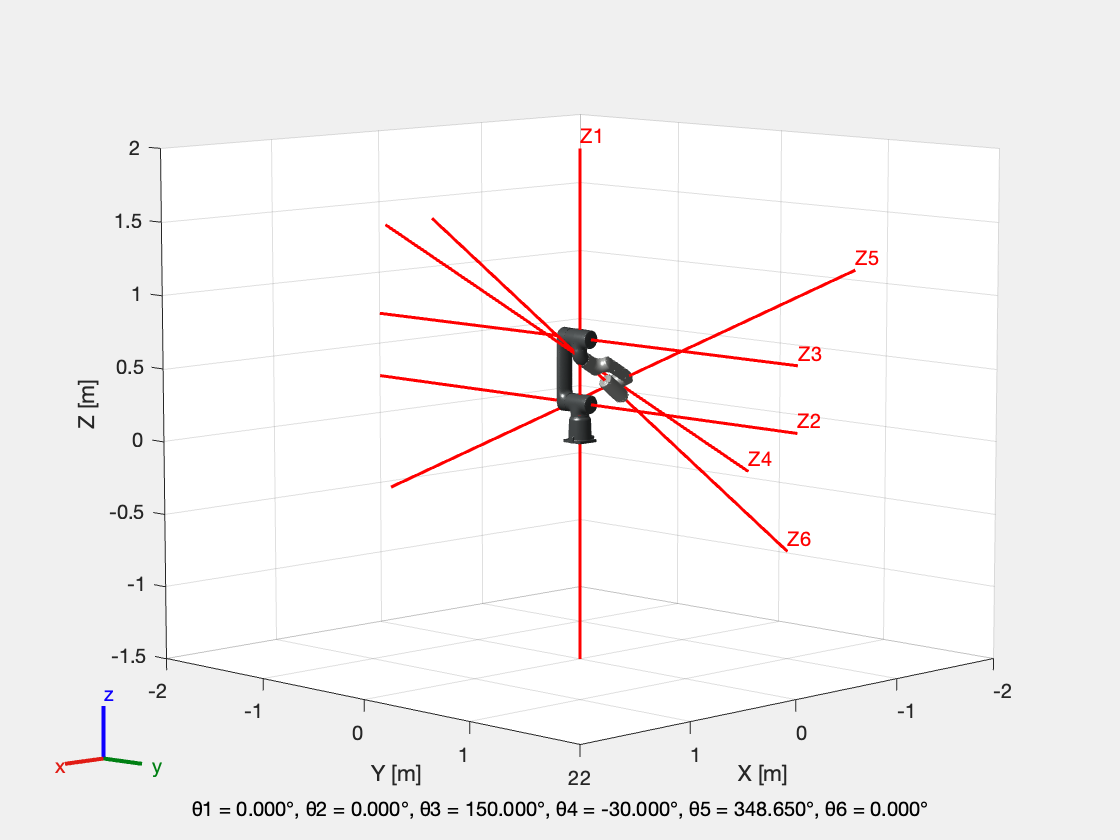


q = [0, tet2_1, tet3_1+pi, tet4_1, pi - tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (4)', q, true, T0i);


vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = \left(\begin{array}{c} 0.000000000000000041213633532968374314946422428583\\ 0.000000000000000041213633532968374314946423246096\\ 0.000000000000000071384107243625634138348080468405\\ 0\\ 0.0000000000000000045334996886265211746441067397807\\ -0.0000000000000000026174172655996065850727628787617 \end{array}\right)$$

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.000000000000000033505980989791058685904113133356$$

**4D joint space**, two surface for tet5 = x and tet5 = x - pi 

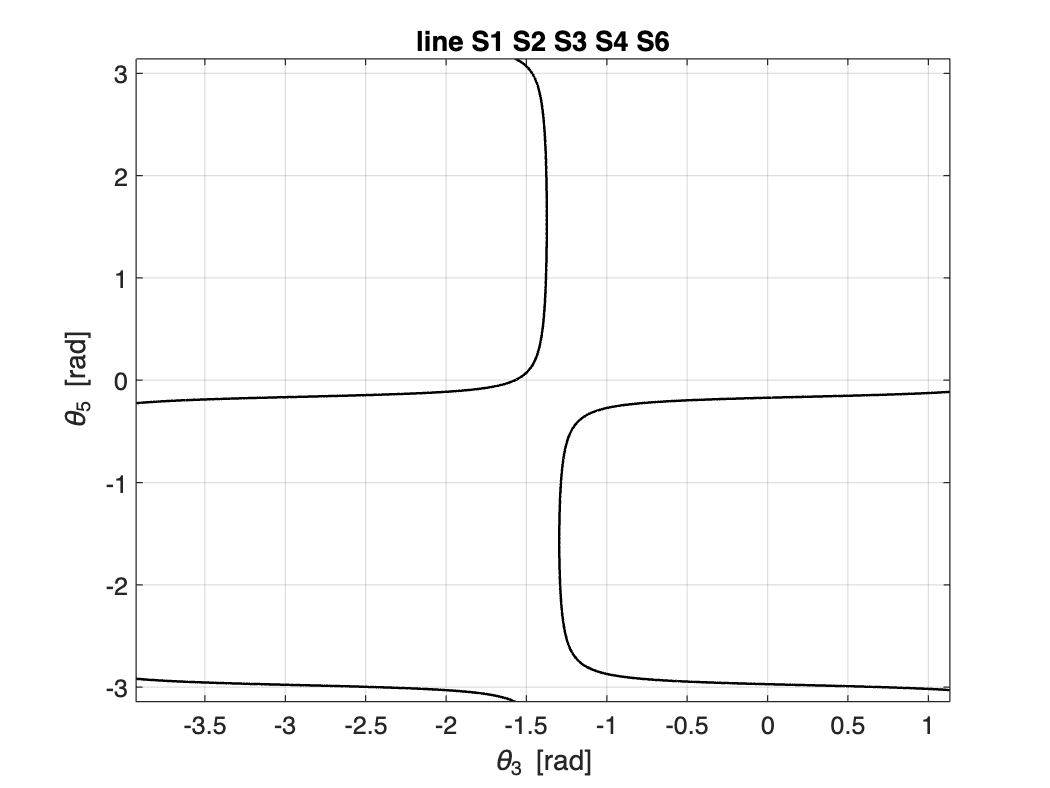

z = @(tet3, tet5) 8*cos(tet3) + sin(tet5).*(47*cos(tet3) + 11*sin(tet3));

range3 = linspace(deg2rad(-225), deg2rad(65), 500);
range5 = linspace(-pi, pi, 500);

[TET3, TET5] = meshgrid(range3, range5);

Z = z(TET3, TET5);

figure;
[C, ~] = contour(TET3, TET5, Z, [0 0], 'LineWidth', 1, 'LineColor', 'k');
xlabel('\theta_3 [rad]');
ylabel('\theta_5 [rad]');
title('line S1 S2 S3 S4 S6');
grid on;
hold on;

saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/line_S2_S3_S4_S6.fig');

z = @(tet3, tet5) 8*cos(tet3) + sin(tet5).*(47*cos(tet3) + 11*sin(tet3));

range3 = linspace(deg2rad(-225), deg2rad(65), 500);
range5 = linspace(-pi, pi, 500);
[TET3, TET5] = meshgrid(range3, range5);
Z = z(TET3, TET5);

[C, ~] = contour(TET3, TET5, Z, [0 0], 'LineWidth', 1, 'LineColor', 'k');

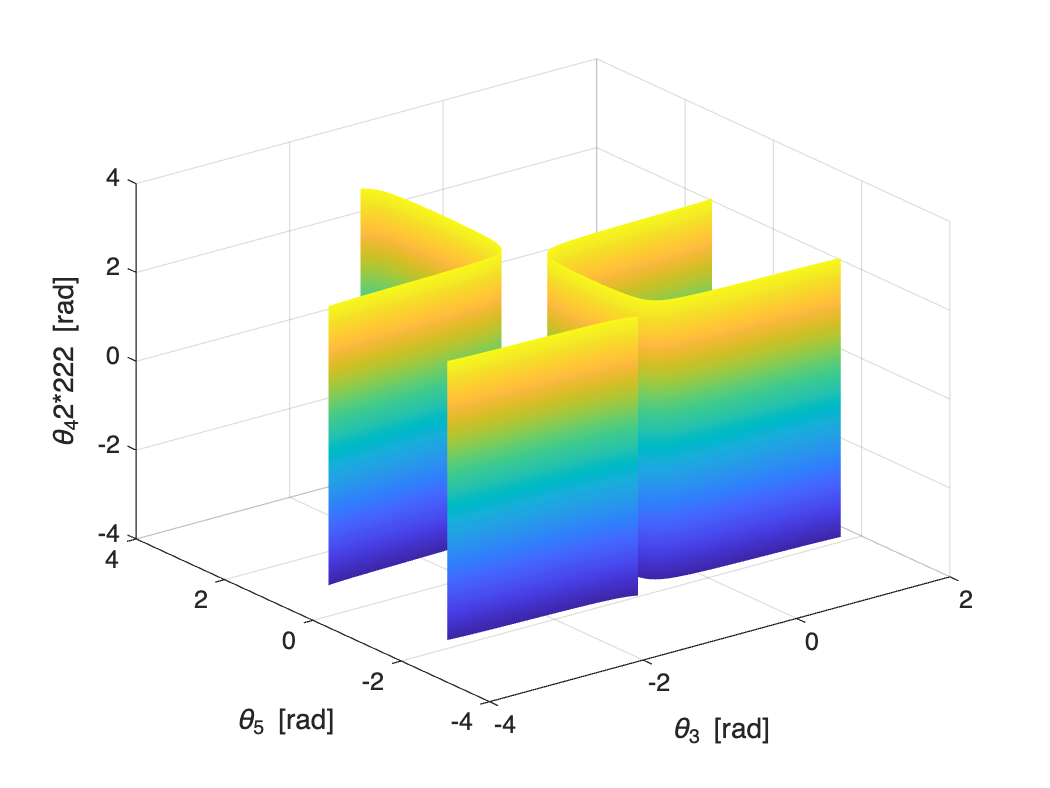


figure;
title('surface S2 S3 S4 S6');

idx = 1;
while idx < size(C,2)
    level = C(1,idx);
    n_points = C(2,idx);
    pts = C(:, idx+1:idx+n_points);
    idx = idx + n_points + 1;

    tet4_range = linspace(-pi, pi, 100);
    [TET4, ~] = meshgrid(tet4_range, 1:n_points);

    tet3_extrude = repmat(pts(1,:)', 1, length(tet4_range));
    tet5_extrude = repmat(pts(2,:)', 1, length(tet4_range));
    tet4_extrude = TET4;

    surf(tet3_extrude, tet5_extrude, tet4_extrude, ...
         'EdgeColor', 'none');
    grid on;
    hold on;
end

xlabel('\theta_3 [rad]');
ylabel('\theta_5 [rad]');
zlabel('\theta_42*222 [rad]');
view(3);


saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/surface_S2_S3_S4_S6.fig');

The total area can be evaluated

A_2346 = 2*14.88*2*pi % 93.49rad^2

A_2346 = 186.9876

**Axes 1, 2, 3, 4 and 6 are normal and intersect a common line**

tet2_1 = 90; % or -90 fixed 
tet3_1 = 0; % or 180 fixed
tet4_1 = 90; % or -90 fixed

wedge = vpa(wedgeProduct(S1, S2, S3, S4, S6));
w = vpa(simplify(subs(wedge, tet2, deg2rad(tet2_1))));
w = vpa(simplify(subs(w, tet3, deg2rad(tet3_1))));
w = vpa(simplify(subs(w, tet4, deg2rad(tet4_1))));

eq = w(6)

$$eq = 0.11560872\,\sin\left({\mathrm{tet}}_{5}\right)+0.01967808$$

sol = vpasolve(eq == 0, tet5, [-pi, pi]);
tet5_1 = double(sol)

tet5_1 = -2.9705

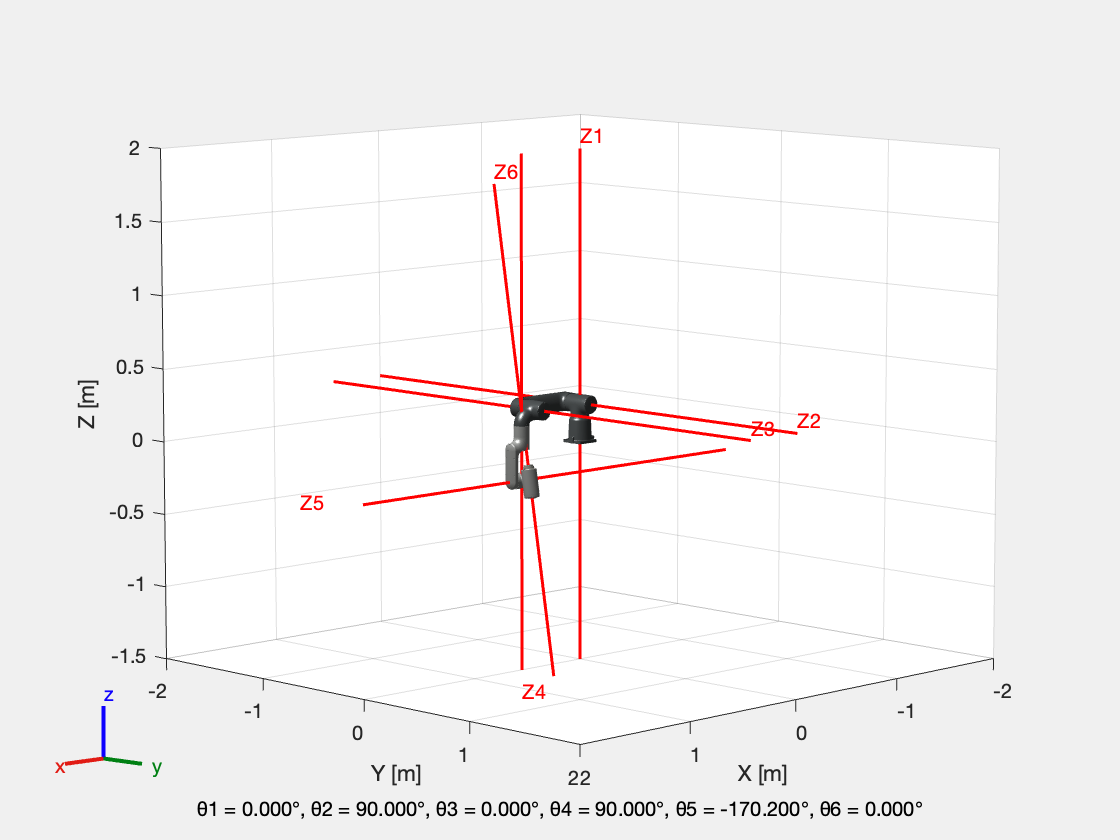


q = [0, deg2rad(tet2_1), deg2rad(tet3_1), deg2rad(tet4_1), tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (5)',q, true, T0i);

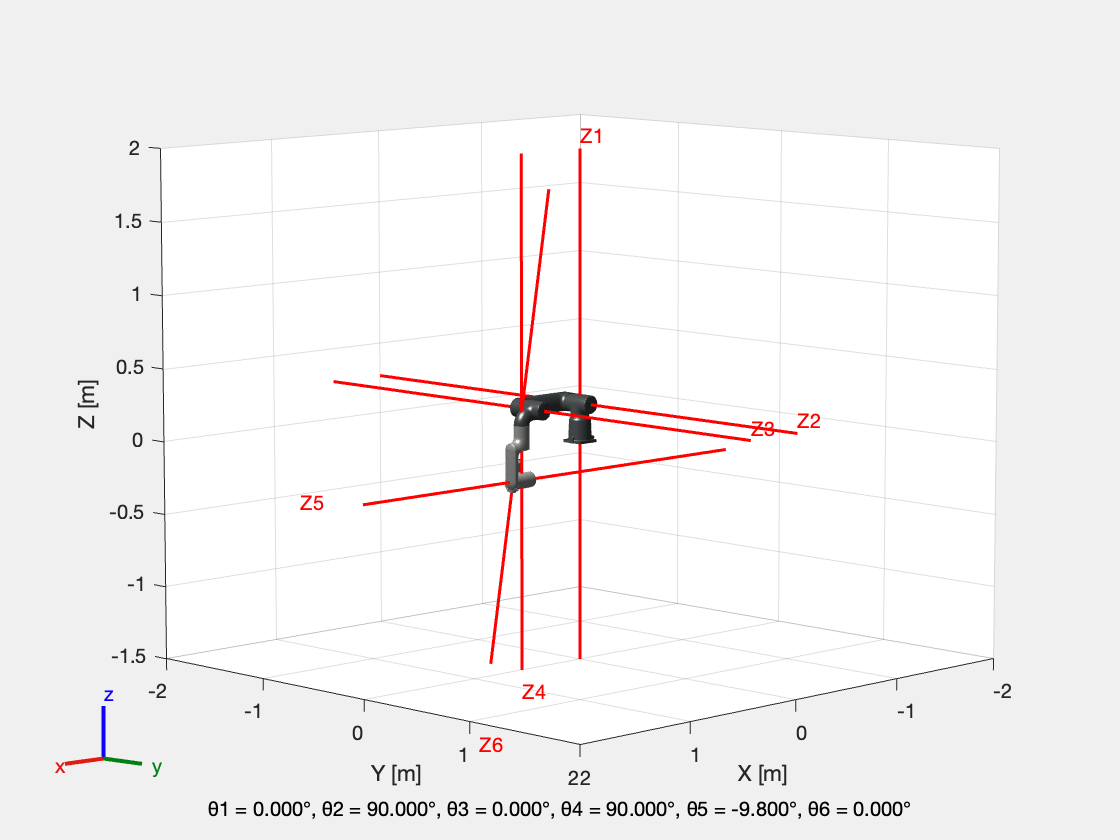


q = [0, deg2rad(tet2_1), deg2rad(tet3_1), deg2rad(tet4_1), -pi-tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, and S6 (6)',q, true, T0i);


vpa(subs(wedge, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ -0.0000000000000000082392283329720623822322797530309 \end{array}\right)$$

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.0000000000000000082392283329720623822322797530309$$

**4D joint space**, 16 points for the 16 combinations

- tet2 = -90° or 90°

- tet3 = 0 or 180°

- tet4 = -90° or 90°

- tet5 = -170.20° or -9.80°

**S1, S2, S3, S4, S5, and S6**

To the best of our knowledge the only possible case is when all axes intersect a common line. This condition can only be met when  tet4 = ±90°

wedge = vpa(simplify(wedgeProduct(S1, S2, S3, S4, S5, S6)))

$$wedge = 0.01577088\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)+0.0053724\,\cos\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0229548\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0166944\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}+0.0039072\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0039072\,{\cos\left({\mathrm{tet}}_{4}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0166944\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.09265392\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.02168496\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.01577088\,\cos\left({\mathrm{tet}}_{3}\right)\,{\cos\left({\mathrm{tet}}_{4}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)+0.0927072\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{5}\right)+0.0459096\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0039072\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.0459096\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0927072\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)$$

**tet4 = ±90°**

w = vpa(simplify(subs(wedge, tet4, pi/2)))

$$w = 0.01577088\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)+0.0053724\,\cos\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0229548\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0166944\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}+0.0039072\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0166944\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.09265392\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.02168496\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0927072\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{5}\right)+0.0459096\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0039072\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.0459096\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0927072\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)$$

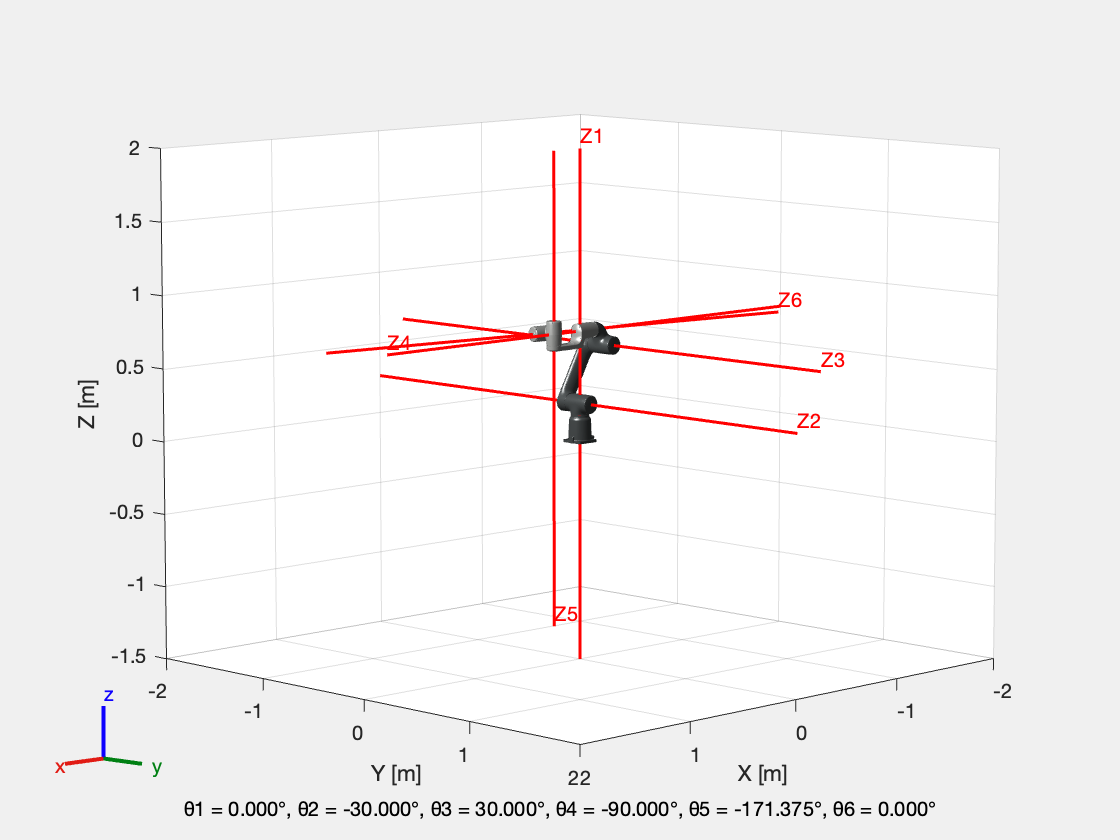


eq = 15.77*cos(tet3) ...
    - 17.58*sin(tet5) ...
    - 12.78*cos(tet3)*sin(tet3) ...
    + 92.65*cos(tet3)*sin(tet5) ...
    + 21.68*sin(tet3)*sin(tet5) ...
    + 20.60*cos(tet3)^2 ...
    + 138.62*cos(tet3)^2*sin(tet5) ...
    - 46.80*cos(tet3)*sin(tet3)*sin(tet5);

tet2_1 = deg2rad(-30);
tet3_1 = deg2rad(30);
tet4_1 = deg2rad(-90);

eq = subs(eq, [tet2, tet3], [tet2_1, tet3_1]);
sol = vpasolve(eq == 0, tet5, [-pi, pi]);
tet5_1 = double(sol);

q = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, S5, and S6 (1)', q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.00000047658926636729123574295701798006$$

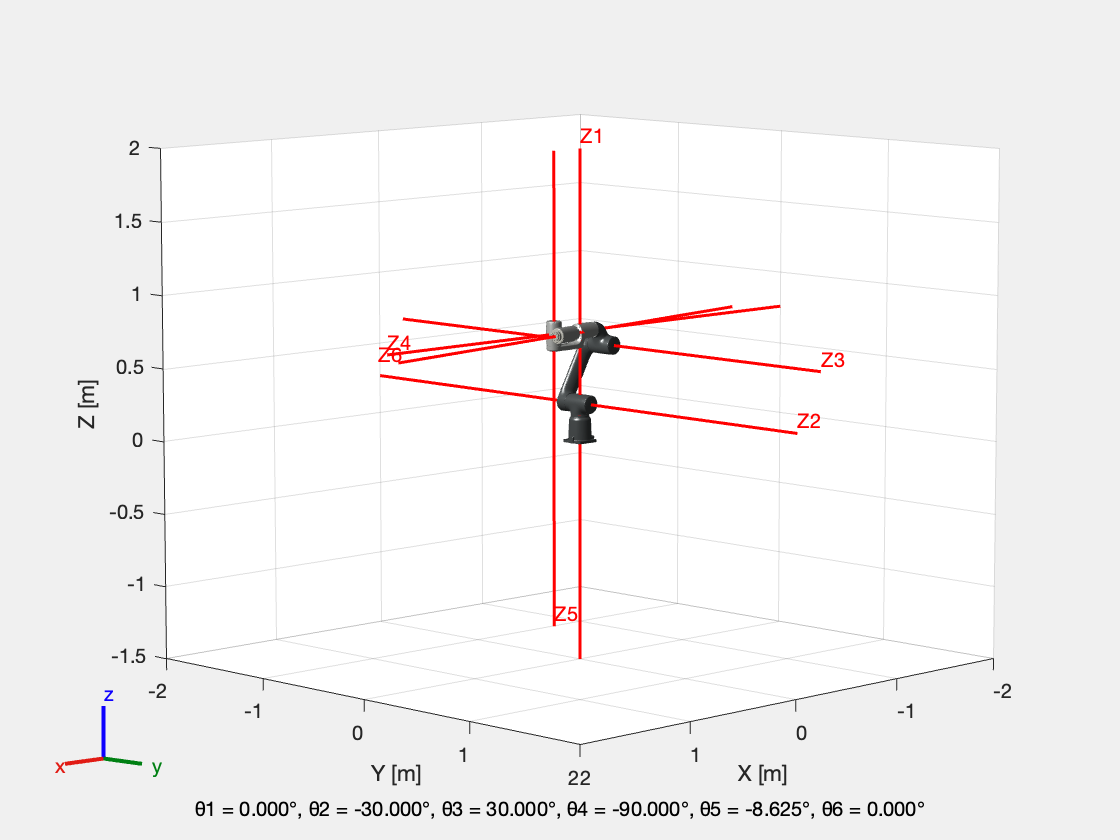


q = [0, tet2_1, tet3_1, tet4_1, -tet5_1-pi, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, S5, and S6 (2)', q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.00000047658926636113126651508556965793$$

**tet4 = 0° or tet4 = 180°**

exaclty the same as singularity **S1, S4 and S6**

w = vpa(simplify(subs(wedge, tet4, 0)))

$$w = 0.0053724\,\cos\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0039072\,\sin\left({\mathrm{tet}}_{2}\right)-0.0229548\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0166944\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}+0.0039072\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0166944\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.09265392\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.02168496\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0927072\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{5}\right)+0.0459096\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0039072\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.0459096\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0927072\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)$$

eq = w

$$eq = 0.0053724\,\cos\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0039072\,\sin\left({\mathrm{tet}}_{2}\right)-0.0229548\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0166944\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}+0.0039072\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0166944\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.09265392\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.02168496\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0927072\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{5}\right)+0.0459096\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0039072\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.0459096\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0927072\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)$$

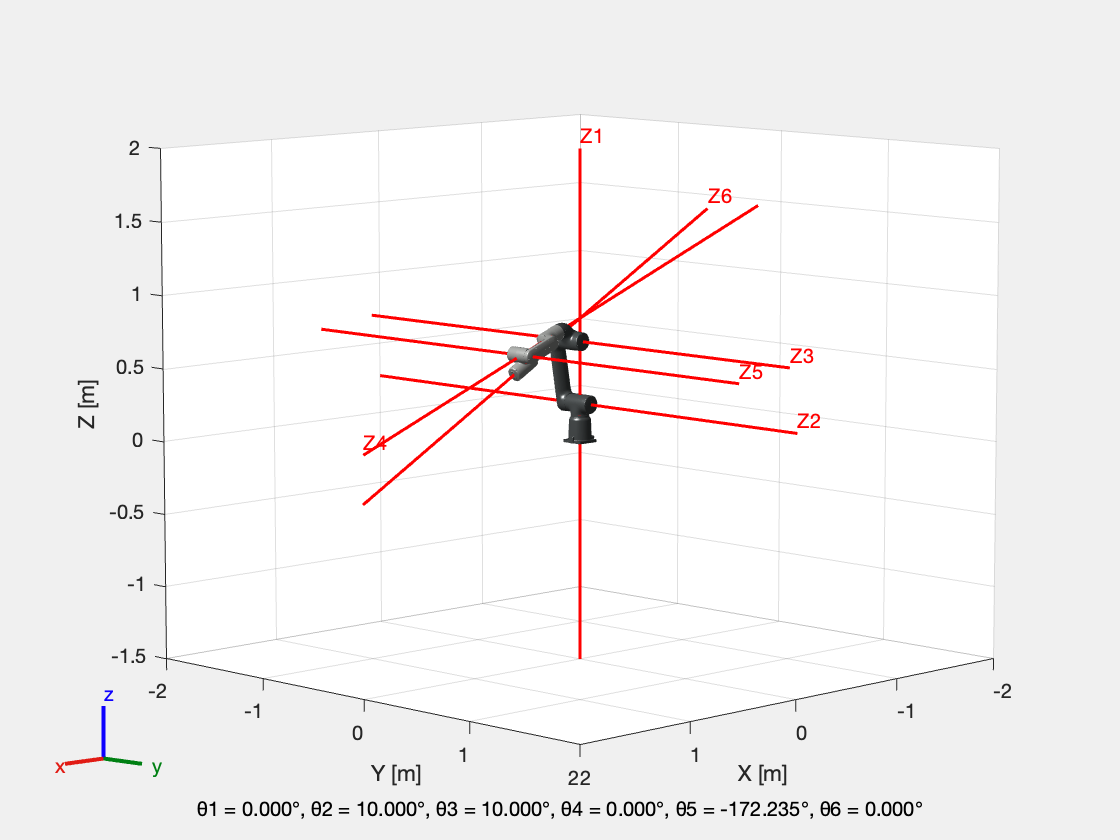


tet2_1 = deg2rad(10);
tet3_1 = deg2rad(10);
tet4_1 = deg2rad(0);

eq = subs(eq, [tet2, tet3], [tet2_1, tet3_1]);
sol = vpasolve(eq == 0, tet5, [-pi, pi]);
tet5_1 = double(sol);

q = [0, tet2_1, tet3_1, tet4_1, tet5_1, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, S5, and S6 (3)', q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.000000000000000015088612884882757819320493991226$$

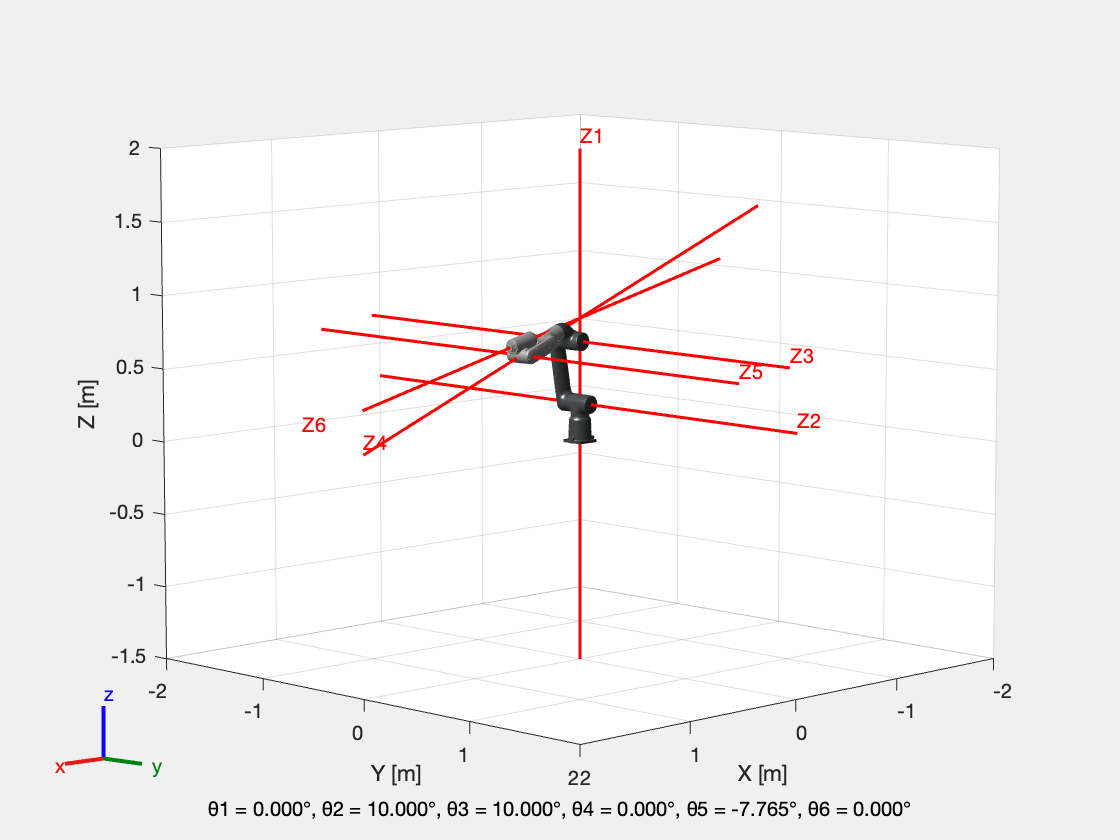


q = [0, tet2_1, tet3_1, tet4_1, -tet5_1-pi, 0];
displayRobot(gofa, 'analysis S1, S2, S3, S4, S5, and S6 (4)', q, true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.0000000000000000006417243820332185373931356881597$$


w = vpa(simplify(subs(wedge, tet4, 0)))

$$w = 0.0053724\,\cos\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0039072\,\sin\left({\mathrm{tet}}_{2}\right)-0.0229548\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0166944\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}+0.0039072\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)-0.0166944\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.09265392\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.02168496\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0927072\,\cos\left({\mathrm{tet}}_{2}\right)\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{5}\right)+0.0459096\,{\cos\left({\mathrm{tet}}_{3}\right)}^{2}\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{5}\right)+0.0039072\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)+0.0459096\,\cos\left({\mathrm{tet}}_{2}\right)\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)-0.0927072\,\cos\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{2}\right)\,\sin\left({\mathrm{tet}}_{3}\right)\,\sin\left({\mathrm{tet}}_{5}\right)$$

w = vpa(subs(w, [tet2 tet3 tet5], deg2rad([30 40 0])))

$$w = 0.0052329602140687948428885496314147$$

4D joint space: two lines that can be extruded into two surfaces 

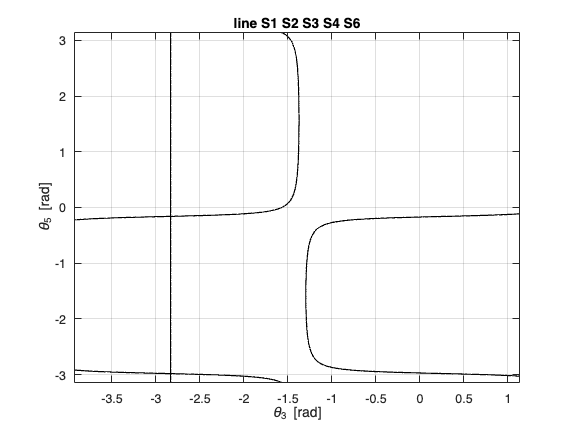

z = @(tet3, tet5) ...
    15.77 * cos(tet3) ...
  - 17.58 * sin(tet5) ...
  - 12.78 * cos(tet3) .* sin(tet3) ...
  + 92.65 * cos(tet3) .* sin(tet5) ...
  + 21.68 * sin(tet3) .* sin(tet5) ...
  + 20.60 * (cos(tet3)).^2 ...
  + 138.62 * (cos(tet3)).^2 .* sin(tet5) ...
  - 46.80 * cos(tet3) .* sin(tet3) .* sin(tet5);

range3 = linspace(deg2rad(-225), deg2rad(65), 500);
range5 = linspace(-pi, pi, 500);

[TET3, TET5] = meshgrid(range3, range5);

Z = z(TET3, TET5);

figure;
[C, ~] = contour(TET3, TET5, Z, [0 0], 'LineWidth', 1, 'LineColor', 'k');
xlabel('\theta_3 [rad]');
ylabel('\theta_5 [rad]');
title('line S1 S2 S3 S4 S6');
grid on;
hold on;


saveas(gcf, '/Users/axel/Desktop/Axel/ETS/CoRo/MatLab/figures/line_S2_S3_S4_S6.fig');

    0.5872



**Test**

q = [0, 0, -76.83, 30.00, 30, 0]

q =          0         0  -76.8300   30.0000   30.0000         0


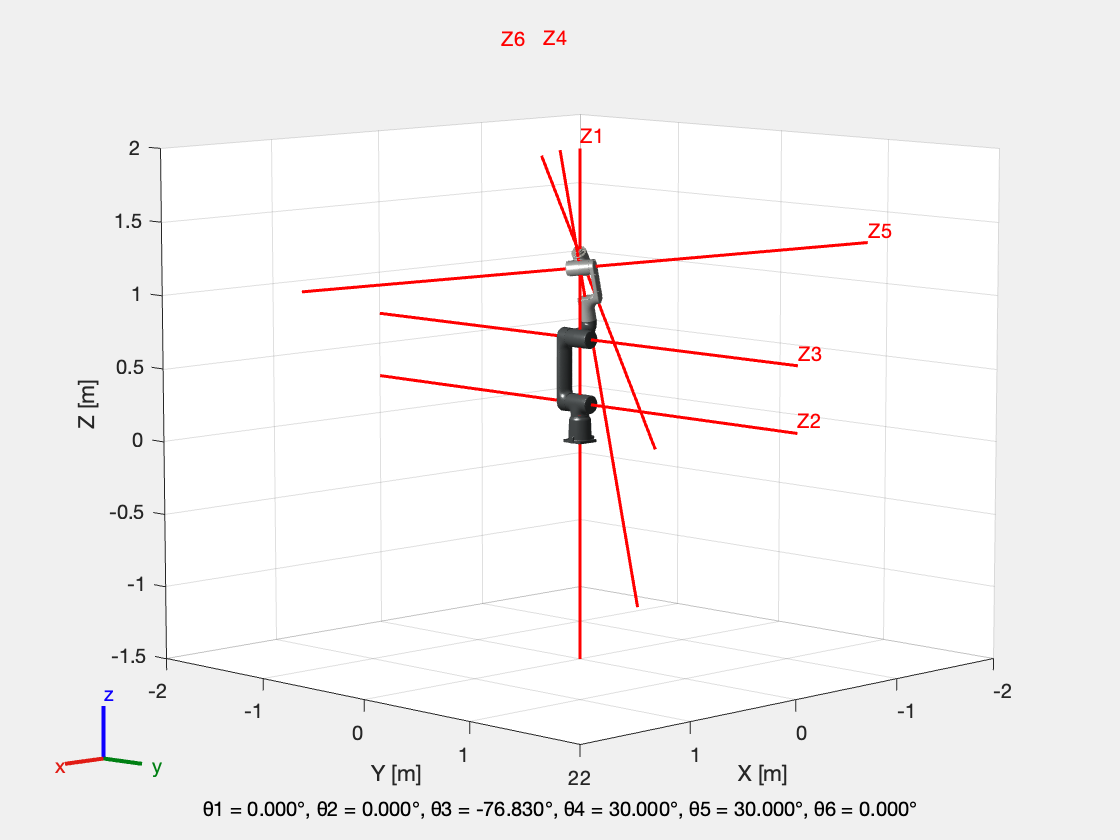

displayRobot(gofa, 'S1 S2 S3 S4 S5', deg2rad(q), true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = -0.0010575972693545214001334209432596$$


q = [0, 0, -30.00, -30.00, -348.65, 0]

q =          0         0  -30.0000  -30.0000 -348.6500         0


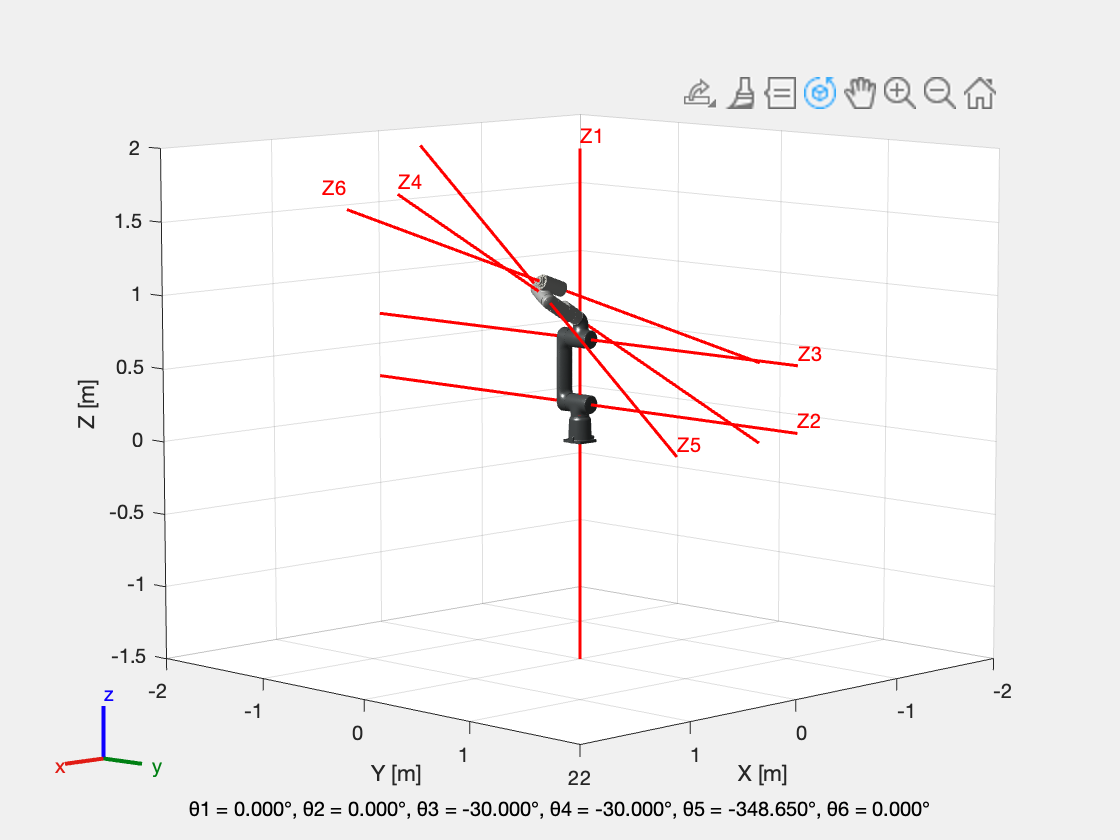

displayRobot(gofa, 'S1 S2 S3 S4 S6', deg2rad(q), true, T0i);

vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = 0.000020028580904317789035049110891124$$

% S1, S2, S3, S5, and S6 ??
% S2, S3 and S5
% S1 and S6
wedge = vpa(simplify(wedgeProduct(S1, S2, S3, S5, S6)))

w = vpa(simplify(subs(wedge, tet4, pi/2)))


eq = 222*cos(tet5)*sin(tet2)+235*cos(tet2+tet3)*cos(tet5)+40*sin(tet2 + tet3)*cos(tet4)+55*sin(tet2+tet3)*cos(tet5)

$$eq = 222\,\cos\left({\mathrm{tet}}_{5}\right)\,\sin\left({\mathrm{tet}}_{2}\right)+235\,\cos\left({\mathrm{tet}}_{2}+{\mathrm{tet}}_{3}\right)\,\cos\left({\mathrm{tet}}_{5}\right)+40\,\sin\left({\mathrm{tet}}_{2}+{\mathrm{tet}}_{3}\right)\,\cos\left({\mathrm{tet}}_{4}\right)+55\,\sin\left({\mathrm{tet}}_{2}+{\mathrm{tet}}_{3}\right)\,\cos\left({\mathrm{tet}}_{5}\right)$$

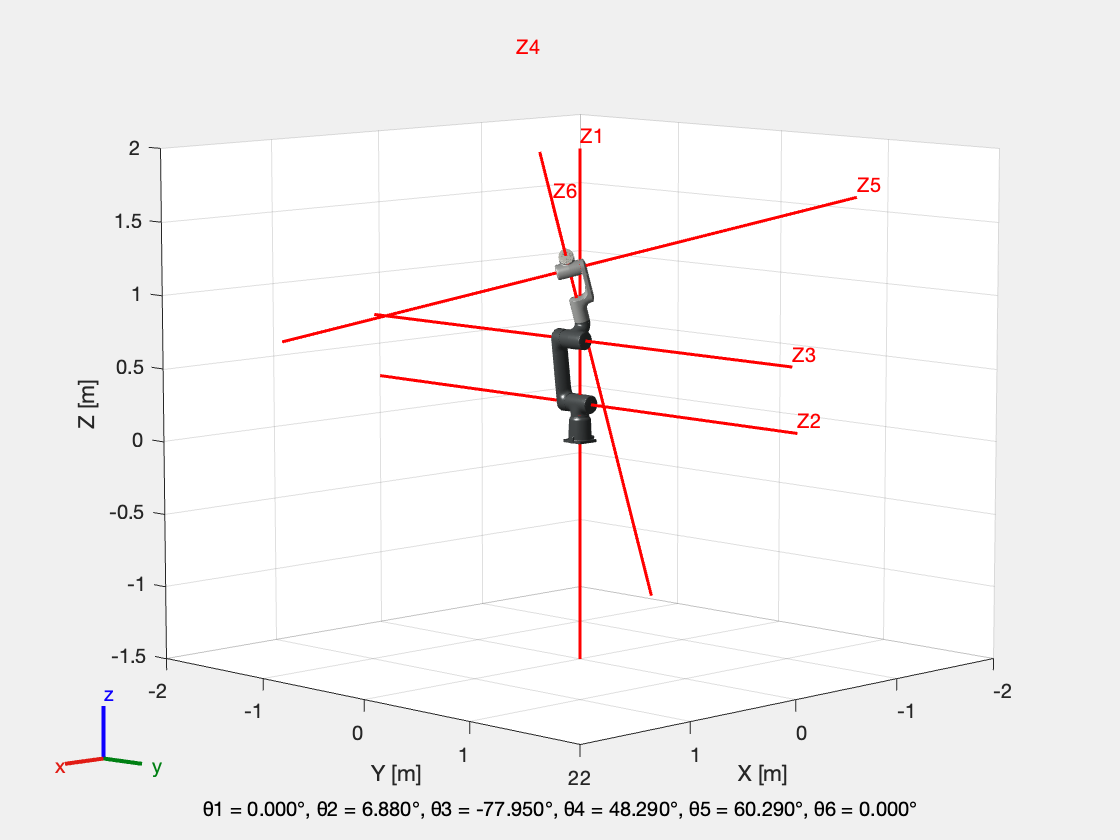


tet2_1 = 0; % or -90
tet3_1 = 0; % or 180
tet4_1 = 0; % or 180

w = vpa(simplify(subs(wedge, tet2, deg2rad(tet2_1))));
w = vpa(simplify(subs(w, tet3, deg2rad(tet3_1))));
w = vpa(simplify(subs(w, tet4, deg2rad(tet4_1))));

%sol = vpasolve(eq == 0, tet5, [-pi, pi]);
%tet5_1 = double(sol)

q = [0, 6.88, -77.95, 48.29, 60.29, 0];
q = deg2rad(q);

displayRobot(gofa, 'default position',q, true, T0i);


vpa(subs(det_J, [tet2, tet3, tet4, tet5], [q(2), q(3), q(4), q(5)]))

$$ans = 0.0000011158498847147908178055281548514$$